# PreProcessing

## Loading all organized datasets

clear
close
load OrganizedDatasetsFull.mat

## PreProcessing organizedData_1, "PoliGaitDatabase_FC SMART"

organizedData_1;
%first we investigate each variable in the excel files to find irregularities and missing values

### Data Exploration (remove/fix)

dropping the 1st and 101st datapoints in all the signals as they are mostly NaN values and offer little predictive power

VariableNamesString_1 = string(organizedData_1.Properties.VariableNames);
varsToRemove_logical_1 = endsWith(VariableNamesString_1,["R1","L1","R101","L101"]);
varsToRemove_1and101_1 =  VariableNamesString_1(varsToRemove_logical_1);

organizedData_1 = removevars(organizedData_1,varsToRemove_1and101_1);

removing some curropted samples (remember, if the final algorithm does not use some specific features, some of the removed files here can be added back to the dataset)

%removing 6.2.1 as it has many missing values (all of kinematic,kinetic,GRF)
organizedData_1(organizedData_1.id_subject == 6 & organizedData_1.id_session == 2 & organizedData_1.id_test == 1, :) = [];

%removing 5.2.2 as spaciotemporal parameters are not valid
organizedData_1(organizedData_1.id_subject == 5 & organizedData_1.id_session == 2 & organizedData_1.id_test == 2, :) = [];

%removing 7.2.1 , 7.2.2 since the ~20 first points of kinematics,kinetics,GRF are missing for them (if the algorithm does no use these features, you can add them later on)
organizedData_1(organizedData_1.id_subject == 7 & organizedData_1.id_session == 2 & organizedData_1.id_test == 1, :) = [];
organizedData_1(organizedData_1.id_subject == 7 & organizedData_1.id_session == 2 & organizedData_1.id_test == 2, :) = [];

%removing 9.2.3 as more than half of kinetic and GRF data are missing
organizedData_1(organizedData_1.id_subject == 9 & organizedData_1.id_session == 2 & organizedData_1.id_test == 3, :) = [];

fixing some curropted samples

%swing time for 3 samples (1.1.3 , 1.2.4 , 5.1.1) are clearly incorrect, they are replaced by a correct estimated value
organizedData_1.swing_R(organizedData_1.id_subject == 1 & organizedData_1.id_session == 1 & organizedData_1.id_test == 3) = ...
    organizedData_1.cycle_time_R(organizedData_1.id_subject == 1 & organizedData_1.id_session == 1 & organizedData_1.id_test == 3) - ...
    organizedData_1.stance_R(organizedData_1.id_subject == 1 & organizedData_1.id_session == 1 & organizedData_1.id_test == 3);

organizedData_1.swing_R(organizedData_1.id_subject == 1 & organizedData_1.id_session == 2 & organizedData_1.id_test == 4) = ...
    organizedData_1.cycle_time_R(organizedData_1.id_subject == 1 & organizedData_1.id_session == 2 & organizedData_1.id_test == 4) - ...
    organizedData_1.stance_R(organizedData_1.id_subject == 1 & organizedData_1.id_session == 2 & organizedData_1.id_test == 4);

organizedData_1.swing_R(organizedData_1.id_subject == 5 & organizedData_1.id_session == 1 & organizedData_1.id_test == 1) = ...
    organizedData_1.cycle_time_R(organizedData_1.id_subject == 5 & organizedData_1.id_session == 1 & organizedData_1.id_test == 1) - ...
    organizedData_1.stance_R(organizedData_1.id_subject == 5 & organizedData_1.id_session == 1 & organizedData_1.id_test == 1);


further fixes by interactively looking at table variables in the output panel of matlab, to see distributions and histograms to identify possible outliers and missing values (remember some sections including this one should be run only once, otherwise the operations will be applied multiple times)

%in the note variable, same category is represented in 2 ways
organizedData_1.note = mergecats(organizedData_1.note,{'HEMI  DX','HEMI DX'},"HEMI DX");

%stance time for 1.2.4 is clearly incorrect, it is replaced by a correct estimated value
organizedData_1.stance_L(organizedData_1.id_subject == 1 & organizedData_1.id_session == 2 & organizedData_1.id_test == 4) = ...
    organizedData_1.cycle_time_L(organizedData_1.id_subject == 1 & organizedData_1.id_session == 2 & organizedData_1.id_test == 4) - ...
    organizedData_1.swing_L(organizedData_1.id_subject == 1 & organizedData_1.id_session == 2 & organizedData_1.id_test == 4);

%double support time for 1.2.4 is clearly incorrect, it is replaced by a correct estimated value (by looking at similar values for other samples, it seems like the decimal point was at the wrong position during input)
organizedData_1.double_support_R(organizedData_1.id_subject == 1 & organizedData_1.id_session == 2 & organizedData_1.id_test == 4) = ...
    organizedData_1.double_support_R(organizedData_1.id_subject == 1 & organizedData_1.id_session == 2 & organizedData_1.id_test == 4) / 10;

%double support time for 6.2.2 is clearly incorrect, it is replaced by a correct estimated value (by looking at similar values for other samples, it seems like the decimal point was at the wrong position during input)
organizedData_1.double_support_R(organizedData_1.id_subject == 6 & organizedData_1.id_session == 2 & organizedData_1.id_test == 2) = ...
    organizedData_1.double_support_R(organizedData_1.id_subject == 6 & organizedData_1.id_session == 2 & organizedData_1.id_test == 2) / 10;

%double support time for 6.2.2 is missing, it is replaced by a possible estimated value
organizedData_1.double_support_L(organizedData_1.id_subject == 6 & organizedData_1.id_session == 2 & organizedData_1.id_test == 2) = ...
    organizedData_1.double_support_R(organizedData_1.id_subject == 6 & organizedData_1.id_session == 2 & organizedData_1.id_test == 2);

up to the end of spaciotemporal is fixed now. 

However, the values of them are not compared to report pdfs to see if they are correct (because kinematic,kinetic,grf data are not always similar to pdf reports)

### Visualization

further fixes by Visualization (kinematics, kinetics, GRF)

- `tests of the same subject are rows of:`

- `    1:7 for subject1`

- `    8:14 for subject2`

- `    15:20 for subject3`

- `    21:26 for sybject4`

- `    27:31 for subject5`

- `    32:36 for subject6`

- `    37:40 for subject7`

- `    41:46 for subject8`

- `    47:51 for subject9`

- `this is not true after the next sections are ran, as some samples are removed in the next sections, the row number for tests will become different`

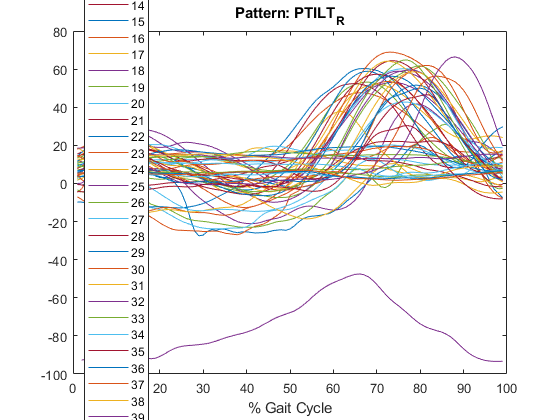

%visualizing kinematic, kinetic and GRF patterns to find weird stuff
%change the three variables below for visualizations of interest
%try to visualize different patterns by superimposing all/uni-subject samples to find outliers (GRF patterns seem weird, maybe they should not be considered in the algorithm, nothing has been done about this yet, all the force components for the right foot seem to represent wrong components but forces of the left foot are correct)
%try to compare righ/left sides of the same patterns, it shows that some inputs were wrong in the data collection phase (e.g. VEF_R seems to have a combination of MLF and APF patterns, this will ruin the algorithm, nothing has been done about it yet, by analzing the real report files VEF_R seems to be incorrect, also MLF_R and APF_R)
beginningRow1_1 =1;
endRow1_1 = 51;
PatternToPlot1_1 = "PTILT_R";




visualization_1=organizedData_1{beginningRow1_1:endRow1_1 ,startsWith(string(organizedData_1.Properties.VariableNames),PatternToPlot1_1)};
plot(1:size(visualization_1,2),visualization_1)
title("Pattern: "+PatternToPlot1_1)
xlabel("% Gait Cycle")
legend(string(beginningRow1_1:endRow1_1),"Location","best")

%by superimposing uni-subjects, some tests are inconsistent with respect to other tests of the same subject. these samples are: 3,7,10,12,(13),(26),(32),(33),(39),41,45,(49) with the ones in parantheses being worst ones that are inconsistent in all kinematic, kinetic, GRF patterns (nothing has been done about it yet)
%HOWEVER, by superimposing all subjects we can observe that the aformentioned samples look simillar to some of the other patients, so the problem might be due to incorrect data input in data collection phase

%32 (6.1.1) has very different values compared to others in kinematics, so it is removed it in the next sections

%some samples have completely shuffeled patterns for all kinematic,kinetic,grf data (e.g. 4.2.2 / 7.1.1) while some other samples are fine (e.g. 2.2.2) while some samples only have problems in grf (9.2.1). nothing has been done about this. you can visualize this by comparing different plots with the report pdfs

after running next sections, 1 sample will be removed, so the number of samples will reduce from 51 to 50 and the plotting might encounter errors, this can be avoided by putting the endRow variable at a maximum of 50 instead of 51.

remember the sample numbers (e.g. 40) do NOT correspond to the same tests now, always try to double-check when you are trying to find the specific test from the sample number, by generating a brand new table at the specific lines of code. Clearing and rerunning the script section by section can help to avoid problems.

further fixes by Visualization (variables)

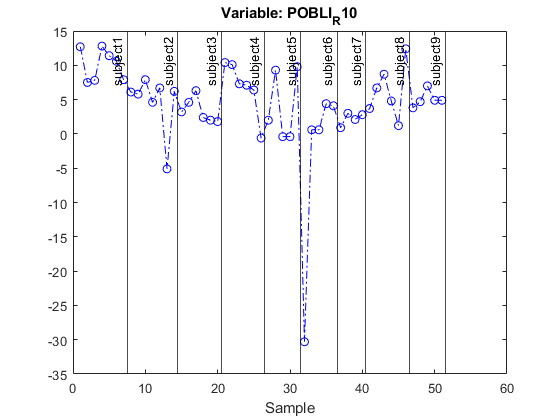

%this can help finding samples that have weird values for each variable (finding outliers)
%as long as observations belonging to the same subject have similar values, things are fine

VariableToPlot_1 = 'POBLI_R10';



plot(organizedData_1{:,VariableToPlot_1},"bo-.")
title("Variable: "+VariableToPlot_1)
xlabel("Sample")
xline(7.5,"k","label","subject1","LabelHorizontalAlignment","left");
xline(14.5,"k","label","subject2","LabelHorizontalAlignment","left");
xline(20.5,"k","label","subject3","LabelHorizontalAlignment","left");

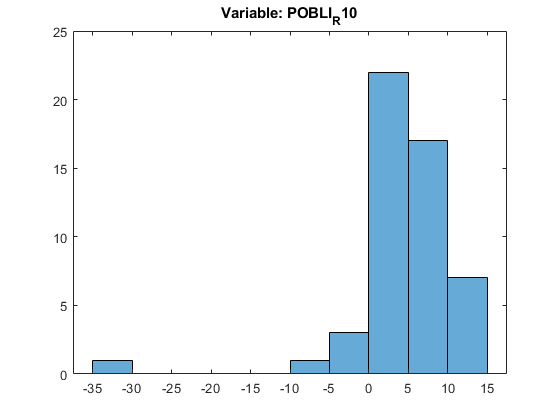

xline(26.5,"k","label","subject4","LabelHorizontalAlignment","left");
xline(31.5,"k","label","subject5","LabelHorizontalAlignment","left");
xline(36.5,"k","label","subject6","LabelHorizontalAlignment","left");
xline(40.5,"k","label","subject7","LabelHorizontalAlignment","left");
xline(46.5,"k","label","subject8","LabelHorizontalAlignment","left");

xline(51.5,"k","label","subject9","LabelHorizontalAlignment","left");
%the values for vertical lines separating subjects will no longer be valid
%after next section is ran, as the number of samples change

histogram(organizedData_1{:,VariableToPlot_1})
title("Variable: "+VariableToPlot_1)



%sample 32 (6.1.1) looks like an outlier (as we found similar results about it in the previous section, so it will be removed in the next section) 

rerunning this section after next section is ran will give us different plots, as one sample (outlier) will be removed

further removing of curropt samples

%removing 6.1.1 as it looks like an outlier (kinematic)
organizedData_1(organizedData_1.id_subject == 6 & organizedData_1.id_session == 1 & organizedData_1.id_test == 1, :) = [];
%now we there are 50 samples in this dataset

### Handling Missing Data

Finding missing values

missing_1 = ismissing(organizedData_1); %all missing values


sumMissingVariableTable_1 = 1×3786 table
    id_subject_SumMissing    id_session_SumMissing    id_test_SumMissing    note_SumMissing    sex_SumMissing    Age_SumMissing    weight_SumMissing    height_SumMissing    System_SumMissing    speed_SumMissing    cadence_SumMissing    cycle_time_R_SumMissing    cycle_time_L_SumMissing    stance_R_SumMissing    stance_L_SumMissing    swing_R_SumMissing    swing_L_SumMissing    double_support_R_SumMissing    double_support_L_SumMissing    stride_length_R_SumMissing    stride_length_L_SumMissing    step_length_R_SumMissing    step_length_L_SumMissing    st



sumMissingVariable_1 = sum(missing_1,1); %the number of missing values for each variable column
sumMissingVariableTable_1 = cell2table(cellstr(string(sumMissingVariable_1)));
sumMissingVariableTable_1.Properties.VariableNames = organizedData_1.Properties.VariableNames + "_SumMissing"
%based on this table, it might be a good idea to remove the variables that have a lot of missing values
%for now we will use interpolation for each pattern to preserve more variables in the dataset
%since the table is too wide, the following code can be used to find the variable with highest number of missing values >
% > [m,idx]=max(sumMissingVariable_1) > sumMissingVariableTable_1(1,idx) % so this variable can be removed


sumMissingSampleTable_1 = 50×4 table
    id_subject    id_session    id_test    SumMissing
    __________    __________    _______    __________

        1             1            1            1    
        1             1            2            9    
        1             1            3           45    
        1             2            1            0    
        1             2            2            0    
        1             2            3            0    
        1             2            4            0    
        2             1            1            0    
        2             1            2            0    
        2             1            3            0    
        2             1            4           44    
        2             2            1           25    
        2             2            2            0    
        2       



sumMissingSample_1 = sum(missing_1,2); %the number of missing values for each sample row
sumMissingSampleTable_1 = table(organizedData_1.id_subject,organizedData_1.id_session,organizedData_1.id_test,sumMissingSample_1);
sumMissingSampleTable_1.Properties.VariableNames = {'id_subject','id_session','id_test','SumMissing'}
%based on this table, it might be a good idea to remove the samples that have a lot of missing values
%for now we will use interpolation for each pattern to preserve more samples in the dataset

maybe the samples that have too many NaNs on the edges of their patterns should be removed here if the interpolation of the next section doesnt work on them well. check it if the final algorithm does not work well

Handling missing values (the methods used for interpolation in this section can be modified later to acquire better results)

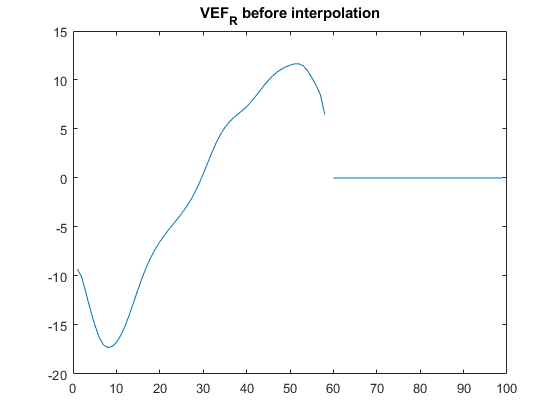

%creating a copy of our dataset for interpolation, which will be the latest dataset that we will work on later on
filledData_1 = organizedData_1;

patternNames_1 = ["POBLI_R" "POBLI_L" "PTILT_R" "PTILT_L" "PROTA_R" "PROTA_L" "HPAA_R" "HPAA_L" "HPFE_R" "HPFE_L" ...
    "HPIE_R" "HPIE_L" "KFE_R" "KFE_L" "KIE_R" "KIE_L" "AFE_R" "AFE_L" "AIE_R" "AIE_L" "HPFEM_R" "HPFEM_L" "KFEM_R" ...
    "KFEM_L" "AFEM_R" "AFEM_L" "HPP_R" "HPP_L" "KP_R" "KP_L" "AP_R" "AP_L" "APF_R" "APF_L" "MLF_R" "MLF_L" "VEF_R" "VEF_L"];
for i_1 = 1:38
    filledData_1{: ,startsWith(string(filledData_1.Properties.VariableNames),patternNames_1(i_1))} = ...
    fillmissing(filledData_1{: ,startsWith(string(filledData_1.Properties.VariableNames),patternNames_1(i_1))},"linear",2);
end
%interpolation is done on each pattern separately, so that the other patterns don't contribute to the process


%you can compare this visualization with the visualization of post-filling to see if things worked correctly
beginningRow2_1 =32;

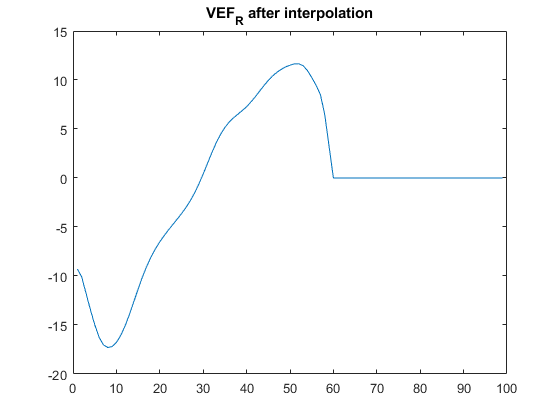

endRow2_1 = 32;
PatternToPlot2_1 = "VEF_R";
visualization_1=organizedData_1{beginningRow2_1:endRow2_1 ,startsWith(string(organizedData_1.Properties.VariableNames),PatternToPlot2_1)};
plot(1:size(visualization_1,2),visualization_1) %plot of pre-interpolation

title(PatternToPlot2_1 + " before interpolation")

visualizationFilled_1=filledData_1{beginningRow2_1:endRow2_1 ,startsWith(string(filledData_1.Properties.VariableNames),PatternToPlot2_1)};
plot(1:size(visualizationFilled_1,2),visualizationFilled_1) %plot of post-interpolation
title(PatternToPlot2_1 + " after interpolation")




sumMissingFilledSampleTable_1 = 50×4 table
    id_subject    id_session    id_test    SumMissing
    __________    __________    _______    __________

        1             1            1           0     
        1             1            2           0     
        1             1            3           0     
        1             2            1           0     
        1             2            2           0     
        1             2            3           0     
        1             2            4           0     
        2             1            1           0     
        2             1            2           0     
        2             1            3           0     
        2             1            4           0     
        2             2            1           0     
        2             2            2           0     
        2 

%furthermore, we can count the number of NaNs after interpolation, which shows there are no NaNs anymore
missingFilled_1 = ismissing(filledData_1);
sumMissingFilledSample_1 = sum(missingFilled_1,2); %the number of missing values for each sample row
sumMissingFilledSampleTable_1 = table(filledData_1.id_subject,filledData_1.id_session,filledData_1.id_test,sumMissingFilledSample_1);
sumMissingFilledSampleTable_1.Properties.VariableNames = {'id_subject','id_session','id_test','SumMissing'}

THIS FILE HAS SOME PROBLEMS

NOTE THAT WE NEED TO CORRECT THE DATA THAT WERE PUT INTO TABLES INCORRECTLY (e.g. GRF data) BY USING THE PDF AND EMT FILES PROVIDED

## PreProcessing organizedData_2, "PoliGaitDatabase_FC SMART_ITOP (Salvato automaticamente)"

organizedData_2;
%first we investigate each variable in the excel files to find irregularities and missing values

### Data Exploration (remove/fix)

dropping the 1st and 101st datapoints in all the signals as they are mostly NaN values and offer little predictive power

VariableNamesString_2 = string(organizedData_2.Properties.VariableNames);
varsToRemove_logical_2 = endsWith(VariableNamesString_2,["R1","L1","R101","L101"]);
varsToRemove_1and101_2 =  VariableNamesString_2(varsToRemove_logical_2);

organizedData_2 = removevars(organizedData_2,varsToRemove_1and101_2);

removing some curropted samples (remember, if the final algorithm does not use some specific features, some of the removed files here can be added back to the dataset)

%removing 12.1.1 as it has weird values (kinetic, GRF)
organizedData_2(organizedData_2.id_subject == 12 & organizedData_2.id_session == 1 & organizedData_2.id_test == 1, :) = [];

%removing 8.3.1 as it has a lot of missing values (kinematic)
organizedData_2(organizedData_2.id_subject == 8 & organizedData_2.id_session == 3 & organizedData_2.id_test == 1, :) = [];

%removing 18.3.2 as it has a lot of missing values (kinematic, GRF)
organizedData_2(organizedData_2.id_subject == 18 & organizedData_2.id_session == 3 & organizedData_2.id_test == 2, :) = [];

%removing 19.1.1 as it has a lot of missing values (kinematic, kinetic)
organizedData_2(organizedData_2.id_subject == 19 & organizedData_2.id_session == 1 & organizedData_2.id_test == 1, :) = [];

%removing 19.2.1 as it has a lot of missing values (kinematic, kinetic)
organizedData_2(organizedData_2.id_subject == 19 & organizedData_2.id_session == 2 & organizedData_2.id_test == 1, :) = [];

%removing 19.2.2 as it has a lot of missing values (kinematic, GRF)
organizedData_2(organizedData_2.id_subject == 19 & organizedData_2.id_session == 2 & organizedData_2.id_test == 2, :) = [];

%removing 6.3.4 as it has a lot of missing values (kinematic, kinetic)
organizedData_2(organizedData_2.id_subject == 6 & organizedData_2.id_session == 3 & organizedData_2.id_test == 4, :) = [];

%removing all the tests for subject 17 as it has missing values for HEIGHT and WEIGHT, if these 2 variables are not important in the final algorithm, this subject can be added to the dataset
organizedData_2(organizedData_2.id_subject == 17, :) = [];

further fixes by interactively looking at table variables in the output panel of matlab, to see distributions and histograms to identify possible outliers and missing values (remember some sections including this one should be run only once, otherwise the operations will be applied multiple times)

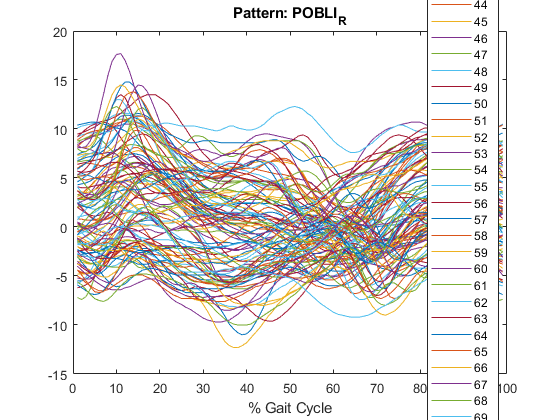

%everything seems to be alright

up to the end of spaciotemporal is fixed now.

However, the values of them are not compared to report pdfs to see if they are correct (because kinematic,kinetic,grf data are not always similar to pdf reports in dataset_1)

### Visualization

further fixes by Visualization (kinematics, kinetics, GRF)

- `tests of the same subject are rows of:`

- `    1:11 for subject1`

- `    12:18 for subject2`

- `    19:37 for subject3`

- `    38:44 for sybject4`

- `    45:52 for subject5`

- `    53:63 for subject6`

- `    64:71 for subject7`

- `    72:82 for subject8`

- `    83:90 for subject9`

- `    91:98 for subject10`

- `    99:110 for subject11`

- `    111:121 for subject12`

- `    122:129 for subject13`

- `    130:136 for subject14`

- `    137:144 for subject15`

- `    145:152 for subject16`

- `    153:161 for subject18`

- `    162:169 for subject19`

- `this is not true after the next sections are ran, as some samples are removed in the next sections, the row number for tests will become different`

%visualizing kinematic, kinetic and GRF patterns to find weird stuff
%change the three variables below for visualizations of interest
%try to visualize different patterns by superimposing all/uni-subject samples to find outliers
%try to compare righ/left sides of the same patterns
beginningRow1_2 =1;
endRow1_2 = 111;
PatternToPlot1_2 = "POBLI_R";



visualization_2=organizedData_2{beginningRow1_2:endRow1_2 ,startsWith(string(organizedData_2.Properties.VariableNames),PatternToPlot1_2)};
plot(1:size(visualization_2,2),visualization_2)
title("Pattern: "+PatternToPlot1_2)
xlabel("% Gait Cycle")
legend(string(beginningRow1_2:endRow1_2),"Location","best")

%by superimposing uni-subjects, some tests are inconsistent with respect to other tests of the same subject. these samples are: 153 (18.1.1) and 157(18.2.1), they are removed in the next sections


after running next sections, 2 samples will be removed, so the number of samples will reduce from 169 to 167 and the plotting might encounter errors, this can be avoided by putting the endRow variable at a maximum of 167 instead of 169.

remember the sample numbers (e.g. 160) do NOT correspond to the same tests now, always try to double-check when you are trying to find the specific test from the sample number, by generating a brand new table at the specific lines of code. Clearing and rerunning the script section by section can help to avoid problems.

further fixes by Visualization (variables)

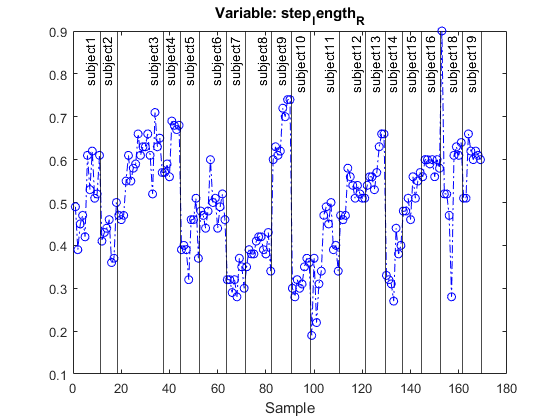

%this can help finding samples that have weird values for each variable (finding outliers)
%as long as observations belonging to the same subject have similar values, things are fine

VariableToPlot_2 = 'step_length_R';



plot(organizedData_2{:,VariableToPlot_2},"bo-.")
title("Variable: "+VariableToPlot_2)
xlabel("Sample")

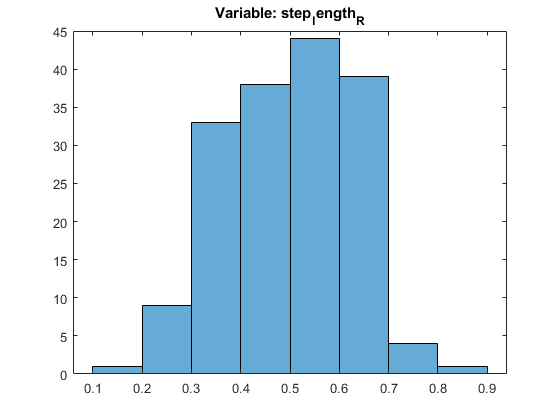

xline(11.5,"k","label","subject1","LabelHorizontalAlignment","left");
xline(18.5,"k","label","subject2","LabelHorizontalAlignment","left");
xline(37.5,"k","label","subject3","LabelHorizontalAlignment","left");
xline(44.5,"k","label","subject4","LabelHorizontalAlignment","left");

xline(52.5,"k","label","subject5","LabelHorizontalAlignment","left");
xline(63.5,"k","label","subject6","LabelHorizontalAlignment","left");
xline(71.5,"k","label","subject7","LabelHorizontalAlignment","left");
xline(82.5,"k","label","subject8","LabelHorizontalAlignment","left");
xline(90.5,"k","label","subject9","LabelHorizontalAlignment","left");
xline(98.5,"k","label","subject10","LabelHorizontalAlignment","left");
xline(110.5,"k","label","subject11","LabelHorizontalAlignment","left");
xline(121.5,"k","label","subject12","LabelHorizontalAlignment","left");
xline(129.5,"k","label","subject13","LabelHorizontalAlignment","left");
xline(136.5,"k","label","subject14","LabelHorizontalAlignment","left");
xline(144.5,"k","label","subject15","LabelHorizontalAlignment","left");
xline(152.5,"k","label","subject16","LabelHorizontalAlignment","left");
xline(161.5,"k","label","subject18","LabelHorizontalAlignment","left");
xline(169.5,"k","label","subject19","LabelHorizontalAlignment","left");
%the values for vertical lines separating subjects will no longer be valid after next section is ran, as the number of samples change

histogram(organizedData_2{:,VariableToPlot_2})
title("Variable: "+VariableToPlot_2)



%sample 153(18.1.1) and 157(18.2.1) look like outliers (as we found similar results about them in the previous section, so they will be removed in the next section) 

rerunning this section after next section is ran will give us different plots, as two samples (outliers) will be removed

further removing of curropt samples

%removing 18.1.1 as it looks like an outlier 

sumMissingVariableTable_2 = 1×3786 table
    id_subject_SumMissing    id_session_SumMissing    id_test_SumMissing    note_SumMissing    sex_SumMissing    Age_SumMissing    weight_SumMissing    height_SumMissing    System_SumMissing    speed_SumMissing    cadence_SumMissing    cycle_time_R_SumMissing    cycle_time_L_SumMissing    stance_R_SumMissing    stance_L_SumMissing    swing_R_SumMissing    swing_L_SumMissing    double_support_R_SumMissing    double_support_L_SumMissing    stride_length_R_SumMissing    stride_length_L_SumMissing    step_length_R_SumMissing    step_length_L_SumMissing    st

organizedData_2(organizedData_2.id_subject == 18 & organizedData_2.id_session == 1 & organizedData_2.id_test == 1, :) = [];

%removing 18.2.1 as it looks like an outlier 
organizedData_2(organizedData_2.id_subject == 18 & organizedData_2.id_session == 2 & organizedData_2.id_test == 1, :) = [];

%now we there are 167 samples in this dataset

sumMissingSampleTable_2 = 167×4 table
    id_subject    id_session    id_test    SumMissing
    __________    __________    _______    __________

        1             1            1           0     
        1             1            2           0     
        1             1            3           0     
        1             1            4           0     
        1             1            5           0     
        1             2            1           0     
        1             2            2           0     
        1             2            3           0     
        1             2            4           0     
        1             2            5           0     
        1             2            6           0     
        2             1            1           0     
        2             1            2           0     
        2      

### Handling Missing Data

Finding missing values

organizedData_2;
missing_2 = ismissing(organizedData_2); %all missing values



sumMissingVariable_2 = sum(missing_2,1); %the number of missing values for each variable column
sumMissingVariableTable_2 = cell2table(cellstr(string(sumMissingVariable_2)));
sumMissingVariableTable_2.Properties.VariableNames = organizedData_2.Properties.VariableNames + "_SumMissing"
%based on this table, it might be a good idea to remove the variables that have a lot of missing values
%for now we will use interpolation for each pattern to preserve more variables in the dataset
%since the table is too wide, the following code can be used to find the variable with highest number of missing values >
% > [m,idx]=max(sumMissingVariable_2) > sumMissingVariableTable_2(1,idx) % so this variable can be removed


sumMissingSample_2 = sum(missing_2,2); %the number of missing values for each sample row
sumMissingSampleTable_2 = table(organizedData_2.id_subject,organizedData_2.id_session,organizedData_2.id_test,sumMissingSample_2);
sumMissingSampleTable_2.Properties.VariableNames = {'id_subject','id_session','id_test','SumMissing'}
%based on this table, it might be a good idea to remove the samples that have a lot of missing values
%for now we will use interpolation for each pattern to preserve more samples in the dataset

maybe the samples that have too many NaNs on the edges of their patterns should be removed here if the interpolation of the next section doesnt work on them well. check it if the final algorithm does not work well

Handling missing values (the methods used for interpolation in this section can be modified later to acquire better results)

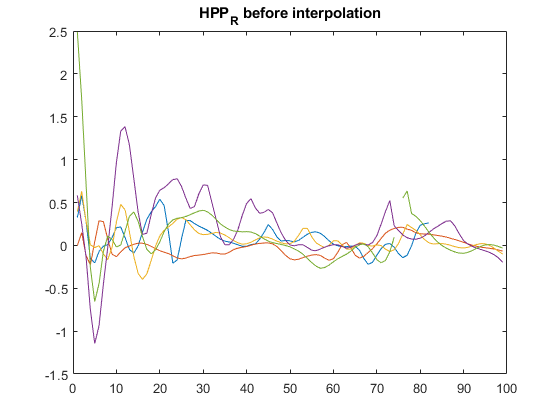

%creating a copy of our dataset for interpolation, which will be the latest dataset that we will work on later on
filledData_2 = organizedData_2;


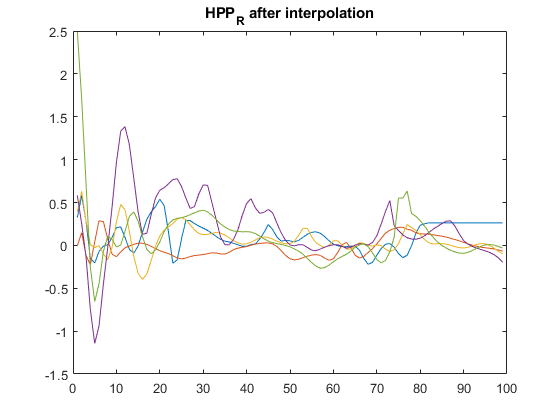

patternNames_2 = ["POBLI_R" "POBLI_L" "PTILT_R" "PTILT_L" "PROTA_R" "PROTA_L" "HPAA_R" "HPAA_L" "HPFE_R" "HPFE_L" ...
    "HPIE_R" "HPIE_L" "KFE_R" "KFE_L" "KIE_R" "KIE_L" "AFE_R" "AFE_L" "AIE_R" "AIE_L" "HPFEM_R" "HPFEM_L" "KFEM_R" ...
    "KFEM_L" "AFEM_R" "AFEM_L" "HPP_R" "HPP_L" "KP_R" "KP_L" "AP_R" "AP_L" "APF_R" "APF_L" "MLF_R" "MLF_L" "VEF_R" "VEF_L"];
for i_2 = 1:38

    filledData_2{: ,startsWith(string(filledData_2.Properties.VariableNames),patternNames_2(i_2))} = ...
    fillmissing(filledData_2{: ,startsWith(string(filledData_2.Properties.VariableNames),patternNames_2(i_2))},"nearest",2);
end
% the method "nearest" works best here, "linear" seems to be very bad


%you can compare this visualization with the visualization of post-filling to see if things worked correctly
beginningRow2_2 =131;
endRow2_2 = 135;
PatternToPlot2_2 = "HPP_R";

sumMissingFilledSampleTable_2 = 167×4 table
    id_subject    id_session    id_test    SumMissing
    __________    __________    _______    __________

        1             1            1           0     
        1             1            2           0     
        1             1            3           0     
        1             1            4           0     
        1             1            5           0     
        1             2            1           0     
        1             2            2           0     
        1             2            3           0     
        1             2            4           0     
        1             2            5           0     
        1             2            6           0     
        2             1            1           0     
        2             1            2           0     
        2

visualization_2=organizedData_2{beginningRow2_2:endRow2_2 ,startsWith(string(organizedData_2.Properties.VariableNames),PatternToPlot2_2)};
plot(1:size(visualization_2,2),visualization_2) %plot of pre-interpolation
title(PatternToPlot2_2 + " before interpolation")

visualizationFilled_2=filledData_2{beginningRow2_2:endRow2_2 ,startsWith(string(filledData_2.Properties.VariableNames),PatternToPlot2_2)};
plot(1:size(visualizationFilled_2,2),visualizationFilled_2) %plot of post-interpolation
title(PatternToPlot2_2 + " after interpolation")





%furthermore, we can count the number of NaNs after interpolation, which shows there are no NaNs anymore
missingFilled_2 = ismissing(filledData_2);
sumMissingFilledSample_2 = sum(missingFilled_2,2); %the number of missing values for each sample row
sumMissingFilledSampleTable_2 = table(filledData_2.id_subject,filledData_2.id_session,filledData_2.id_test,sumMissingFilledSample_2);
sumMissingFilledSampleTable_2.Properties.VariableNames = {'id_subject','id_session','id_test','SumMissing'}

THIS FILE SEEMS TO BE FINE, NO NEED FOR REPORT PDFS

## PreProcessing organizedData_3, "PoliGaitDatabase_FC ELITE - Diplegici"

organizedData_3;
%first we investigate each variable in the excel files to find irregularities and missing values

### Data Exploration (remove/fix)

dropping the 1st and 101st datapoints in all the signals as they are mostly NaN values and offer little predictive power

VariableNamesString_3 = string(organizedData_3.Properties.VariableNames);
varsToRemove_logical_3 = endsWith(VariableNamesString_3,["R1","L1","R101","L101"]);
varsToRemove_1and101_3 =  VariableNamesString_3(varsToRemove_logical_3);

organizedData_3 = removevars(organizedData_3,varsToRemove_1and101_3);

removing some curropted samples (remember, if the final algorithm does not use some specific features, some of the removed files here can be added back to the dataset)

in this dataset it seems like many NaNs are represented as zeros, so the samples that have a lot of zeros are also removed here

%removing 3.1.1 as it has many missing values (kinematic, kinetic, GRF)
organizedData_3(organizedData_3.id_subject == 3 & organizedData_3.id_session == 1 & organizedData_3.id_test == 1, :) = [];

%removing 3.1.3 as it has many missing values (spaciotemporal, kinematic, kinetic)
organizedData_3(organizedData_3.id_subject == 3 & organizedData_3.id_session == 1 & organizedData_3.id_test == 3, :) = [];

%removing 9.1.3 as it has many missing values (kinematic, kinetic)
organizedData_3(organizedData_3.id_subject == 9 & organizedData_3.id_session == 1 & organizedData_3.id_test == 3, :) = [];

%removing 11.1.1 as it has many missing values (kinematic)
organizedData_3(organizedData_3.id_subject == 11 & organizedData_3.id_session == 1 & organizedData_3.id_test == 1, :) = [];

%removing 11.1.3 as it has many missing values (kinematic, kinetic, GRF)
organizedData_3(organizedData_3.id_subject == 11 & organizedData_3.id_session == 1 & organizedData_3.id_test == 3, :) = [];

%removing 14.1.1 as it has many missing values (kinematic, kinetic)
organizedData_3(organizedData_3.id_subject == 14 & organizedData_3.id_session == 1 & organizedData_3.id_test == 1, :) = [];

%removing 16.1.3 as it has many missing values (kinetic)
organizedData_3(organizedData_3.id_subject == 16 & organizedData_3.id_session == 1 & organizedData_3.id_test == 3, :) = [];

%removing 17.1.1 as it has many missing values (kinematic, kinetic)
organizedData_3(organizedData_3.id_subject == 17 & organizedData_3.id_session == 1 & organizedData_3.id_test == 1, :) = [];

%removing 17.1.2 as it has many missing values (kinematic, kinetic)
organizedData_3(organizedData_3.id_subject == 17 & organizedData_3.id_session == 1 & organizedData_3.id_test == 2, :) = [];

%removing 17.1.3 as it has many missing values (kinematic, kinetic)
organizedData_3(organizedData_3.id_subject == 17 & organizedData_3.id_session == 1 & organizedData_3.id_test == 3, :) = [];

%removing 18.1.1 as it has many missing values (spaciotemporal, kinematic, kinetic)
organizedData_3(organizedData_3.id_subject == 18 & organizedData_3.id_session == 1 & organizedData_3.id_test == 1, :) = [];

%removing 18.1.2 as it has many missing values (kinematic, kinetic)
organizedData_3(organizedData_3.id_subject == 18 & organizedData_3.id_session == 1 & organizedData_3.id_test == 2, :) = [];

%removing 18.1.3 as it has many missing values (kinematic, kinetic)
organizedData_3(organizedData_3.id_subject == 18 & organizedData_3.id_session == 1 & organizedData_3.id_test == 3, :) = [];

%removing 24.1.1 as it has many missing values (kinematic, kinetic)
organizedData_3(organizedData_3.id_subject == 24 & organizedData_3.id_session == 1 & organizedData_3.id_test == 1, :) = [];

%removing 25.1.1 as it has many missing values (kinematic, kinetic)
organizedData_3(organizedData_3.id_subject == 25 & organizedData_3.id_session == 1 & organizedData_3.id_test == 1, :) = [];

%removing 26.1.1 as it has many missing values (kinematic, kinetic)
organizedData_3(organizedData_3.id_subject == 26 & organizedData_3.id_session == 1 & organizedData_3.id_test == 1, :) = [];

%removing 26.1.3 as it has many missing values (kinetic)
organizedData_3(organizedData_3.id_subject == 26 & organizedData_3.id_session == 1 & organizedData_3.id_test == 3, :) = [];

%removing 27.1.1 as it has many missing values (kinematic, kinetic)
organizedData_3(organizedData_3.id_subject == 27 & organizedData_3.id_session == 1 & organizedData_3.id_test == 1, :) = [];

%removing 28.1.1 as it has many missing values (spaciotemporal)
organizedData_3(organizedData_3.id_subject == 28 & organizedData_3.id_session == 1 & organizedData_3.id_test == 1, :) = [];

%removing 28.1.3 as it has many missing values (spaciotemporal, kinematic, kinetic, GRF)
organizedData_3(organizedData_3.id_subject == 28 & organizedData_3.id_session == 1 & organizedData_3.id_test == 3, :) = [];

%removing 28.1.4 as it has many missing values (spaciotemporal, kinematic, kinetic, GRF)
organizedData_3(organizedData_3.id_subject == 28 & organizedData_3.id_session == 1 & organizedData_3.id_test == 4, :) = [];

%removing 30.1.1 as it has many missing values (kinematic)
organizedData_3(organizedData_3.id_subject == 30 & organizedData_3.id_session == 1 & organizedData_3.id_test == 1, :) = [];

%removing 30.1.2 as it has many missing values (kinematic, kinetic)
organizedData_3(organizedData_3.id_subject == 30 & organizedData_3.id_session == 1 & organizedData_3.id_test == 2, :) = [];

%removing 30.1.3 as it has many missing values (kinematic)
organizedData_3(organizedData_3.id_subject == 30 & organizedData_3.id_session == 1 & organizedData_3.id_test == 3, :) = [];

%removing 32.1.3 as it has many missing values (kinematic, kinetic)
organizedData_3(organizedData_3.id_subject == 32 & organizedData_3.id_session == 1 & organizedData_3.id_test == 3, :) = [];

%removing 35.1.2 as it has many missing values (kinematic, kinetic, GRF)
organizedData_3(organizedData_3.id_subject == 35 & organizedData_3.id_session == 1 & organizedData_3.id_test == 2, :) = [];

%removing 39.1.1 as it has many missing values (spaciotemporal, kinematic, kinetic)
organizedData_3(organizedData_3.id_subject == 39 & organizedData_3.id_session == 1 & organizedData_3.id_test == 1, :) = [];

%removing 39.1.2 as it has many missing values (kinematic, kinetic)
organizedData_3(organizedData_3.id_subject == 39 & organizedData_3.id_session == 1 & organizedData_3.id_test == 2, :) = [];

%removing 40.1.1 as it has many missing values (kinematic, kinetic)
organizedData_3(organizedData_3.id_subject == 40 & organizedData_3.id_session == 1 & organizedData_3.id_test == 1, :) = [];

%removing 42.1.1 as it has many missing values (kinematic, kinetic)
organizedData_3(organizedData_3.id_subject == 42 & organizedData_3.id_session == 1 & organizedData_3.id_test == 1, :) = [];

%removing 42.1.2 as it has many missing values (kinematic)
organizedData_3(organizedData_3.id_subject == 42 & organizedData_3.id_session == 1 & organizedData_3.id_test == 2, :) = [];

%removing 42.1.3 as it has many missing values (kinematic, kinetic)
organizedData_3(organizedData_3.id_subject == 42 & organizedData_3.id_session == 1 & organizedData_3.id_test == 3, :) = [];

%removing 43.1.1 as it has many missing values (spaciotemporal, kinematic, kinetic, GRF)
organizedData_3(organizedData_3.id_subject == 43 & organizedData_3.id_session == 1 & organizedData_3.id_test == 1, :) = [];

%removing 43.1.2 as it has many missing values (spaciotemporal)
organizedData_3(organizedData_3.id_subject == 43 & organizedData_3.id_session == 1 & organizedData_3.id_test == 2, :) = [];

%removing 44.1.2 as it has many missing values (spaciotemporal)
organizedData_3(organizedData_3.id_subject == 44 & organizedData_3.id_session == 1 & organizedData_3.id_test == 2, :) = [];

%removing 48.1.2 as it has many missing values (kinematic, kinetic)
organizedData_3(organizedData_3.id_subject == 48 & organizedData_3.id_session == 1 & organizedData_3.id_test == 2, :) = [];

%removing 48.1.3 as it has many missing values (kinematic, kinetic)
organizedData_3(organizedData_3.id_subject == 48 & organizedData_3.id_session == 1 & organizedData_3.id_test == 3, :) = [];

%removing 48.1.4 as it has many missing values (kinematic, kinetic)
organizedData_3(organizedData_3.id_subject == 48 & organizedData_3.id_session == 1 & organizedData_3.id_test == 4, :) = [];

%removing 57.1.2 as it has many missing values (kinematic, kinetic)
organizedData_3(organizedData_3.id_subject == 57 & organizedData_3.id_session == 1 & organizedData_3.id_test == 2, :) = [];

%removing 58.1.1 as it has many missing values (spaciotemporal, kinematic, kinetic)
organizedData_3(organizedData_3.id_subject == 58 & organizedData_3.id_session == 1 & organizedData_3.id_test == 1, :) = [];


further fixes by interactively looking at table variables in the output panel of matlab, to see distributions and histograms to identify possible outliers and missing values (remember some sections including this one should be run only once, otherwise the operations will be applied multiple times)

%in the sex variable, we have some unknowns, we replace them by M for convenience as it does not affect the final algorithm
organizedData_3.sex = mergecats(organizedData_3.sex,{'M','?','?(m)'},"M");

%in the system variable, we have a missing entry which is supposed to be the same as the others
organizedData_3.System = fillmissing(organizedData_3.System,"constant","ELITE");

%in the cycle_time_L variable, we have a missing value that is replaced by the average of this variable
organizedData_3.cycle_time_L = fillmissing(organizedData_3.cycle_time_L,"constant",mean(organizedData_3.cycle_time_L,'omitnan'));

%swing_L for 5.1.1 is clearly incorrect, it is replaced by a correct estimated value (by looking at similar values for other samples, it seems like the decimal point was at the wrong position during input)
organizedData_3.swing_L(organizedData_3.id_subject == 5 & organizedData_3.id_session == 1 & organizedData_3.id_test == 1) = ...
    organizedData_3.swing_L(organizedData_3.id_subject == 5 & organizedData_3.id_session == 1 & organizedData_3.id_test == 1) / 10;

%in the double_support_R variable, we have some missing values that are replaced by the average of this variable
organizedData_3.double_support_R = fillmissing(organizedData_3.double_support_R,"constant",mean(organizedData_3.double_support_R,'omitnan'));

%in the double_support_L variable, we have some missing values that are replaced by the average of this variable
organizedData_3.double_support_L = fillmissing(organizedData_3.double_support_L,"constant",mean(organizedData_3.double_support_L,'omitnan'));

%in the stride_length_R variable, we have some missing values that are replaced by the average of this variable
organizedData_3.stride_length_R = fillmissing(organizedData_3.stride_length_R,"constant",mean(organizedData_3.stride_length_R,'omitnan'));

%in the step_length_R variable, we have some missing values that are replaced by the average of this variable
organizedData_3.step_length_R = fillmissing(organizedData_3.step_length_R,"constant",mean(organizedData_3.step_length_R,'omitnan'));

%in the step_length_L variable, we have some missing values that are replaced by the average of this variable
organizedData_3.step_length_L = fillmissing(organizedData_3.step_length_L,"constant",mean(organizedData_3.step_length_L,'omitnan'));

%in the step_width variable, we have some missing values that are replaced by the average of this variable
organizedData_3.step_width = fillmissing(organizedData_3.step_width,"constant",mean(organizedData_3.step_width,'omitnan'));

%step_width for 1.1.3 is clearly incorrect, it is replaced by a correct estimated value (by looking at similar values for other samples, it seems like the decimal point was at the wrong position during input)
organizedData_3.step_width(organizedData_3.id_subject == 1 & organizedData_3.id_session == 1 & organizedData_3.id_test == 3) = ...
    organizedData_3.step_width(organizedData_3.id_subject == 1 & organizedData_3.id_session == 1 & organizedData_3.id_test == 3) / 10;

organizedData_3 = 143×3786 table
    id_subject    id_session    id_test    note     sex    Age    weight    height    System    speed    cadence    cycle_time_R    cycle_time_L    stance_R    stance_L    swing_R    swing_L    double_support_R    double_support_L    stride_length_R    stride_length_L    step_length_R    step_length_L    step_width    POBLI_R2    POBLI_R3    POBLI_R4    POBLI_R5     POBLI_R6    POBLI_R7    POBLI_R8    POBLI_R9    

up to the end of spaciotemporal is fixed now.

However, the values of them are not compared to report pdfs to see if they are correct (because kinematic,kinetic,grf data are not always similar to pdf reports in dataset_1)

(attention: this section is written after visualization analysis of the next section)

replacing incorrect zeros with NaN

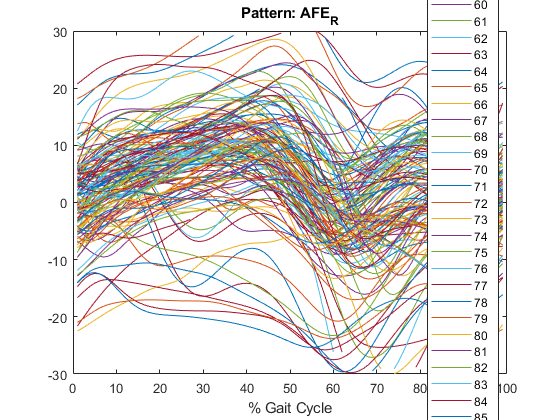

%we can see a lot of missplaced zeros in the graphs, it is evident that some NaNs where replaced with zeros in the original dataset, we need to replace them with NaN again and interpolate later on (except for GRF data that naturally has a lot of zeros in the second half)

%first, we need to define kinematic and kinetic parts of dataset to replace their zeros (even if some zeros are true zeros, they will be derived again in the interpolation process in the coming sections)
allPatternsExceptGRF_3 = ["POBLI_R" "POBLI_L" "PTILT_R" "PTILT_L" "PROTA_R" "PROTA_L" "HPAA_R" "HPAA_L" "HPFE_R" "HPFE_L" ...
    "HPIE_R" "HPIE_L" "KFE_R" "KFE_L" "KIE_R" "KIE_L" "AFE_R" "AFE_L" "AIE_R" "AIE_L" "HPFEM_R" "HPFEM_L" "KFEM_R" ...
    "KFEM_L" "AFEM_R" "AFEM_L" "HPP_R" "HPP_L" "KP_R" "KP_L" "AP_R" "AP_L"];

%now we replace zeros with NaN
organizedData_3(:,startsWith(string(organizedData_3.Properties.VariableNames),allPatternsExceptGRF_3)) = ...
    standardizeMissing(organizedData_3(:,startsWith(string(organizedData_3.Properties.VariableNames),allPatternsExceptGRF_3)),[NaN 0])

%by rerunning the visualizations in the next section we can see that inconsistencies of zeros are gone

### Visualization

further fixes by Visualization (kinematics, kinetics, GRF)

- `tests of the same subject are rows of:`

- `    1:3 for subject1`

- `    4:6 for subject2`

- `    7:7 for subject3`

- `    8:10 for subject4`

- `    11:13 for subject5`

- `    14:16 for subject6`

- `        .`

- `        .`

- `        .`

- `        .`

- `        .`

- `    (60 subjects!)`

- `this is not true after the next sections are ran, as some samples are removed in the next sections, the row number for tests will become different`

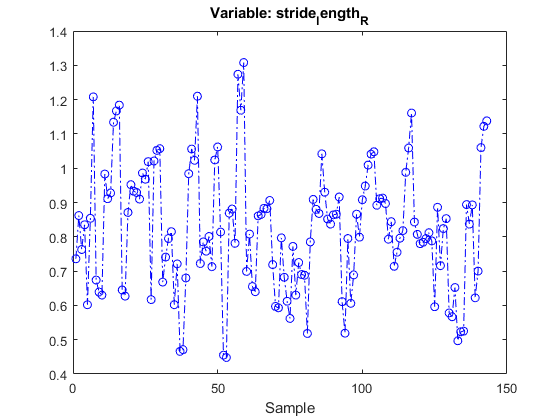

%visualizing kinematic, kinetic and GRF patterns to find weird stuff
%change the three variables below for visualizations of interest
%try to visualize different patterns by superimposing all/uni-subject samples to find outliers
%try to compare righ/left sides of the same patterns
beginningRow1_3 =1;
endRow1_3 = 143;
PatternToPlot1_3 = "AFE_R";




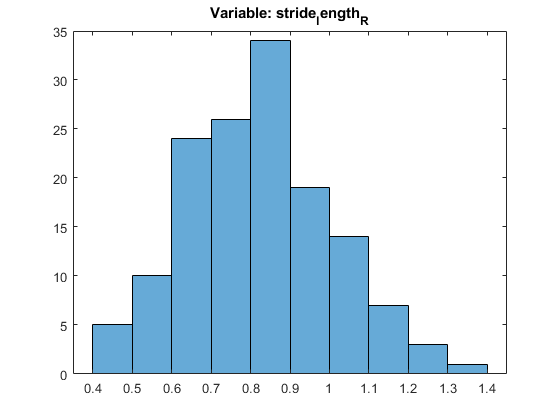

visualization_3=organizedData_3{beginningRow1_3:endRow1_3 ,startsWith(string(organizedData_3.Properties.VariableNames),PatternToPlot1_3)};
plot(1:size(visualization_3,2),visualization_3)
title("Pattern: "+PatternToPlot1_3)

xlabel("% Gait Cycle")
legend(string(beginningRow1_3:endRow1_3),"Location","best")

%by superimposing subjects, it is evident that knee rotation is missing for all samples, so knee rotation variables should be dropped before concatenating the 4 datasets
%remember in the final algorithm, it might be a good idea to use only the first half of GRF data in all datasets, as the second half is inconsistent and mostly zeros

%samples 49 (21.1.1), 126 (53.1.3), 140 (59.1.2) look like outliers, they are removed in the next sections

after running next sections, 3 samples will be removed, so the number of samples will reduce from 143 to 140 and the plotting might encounter errors, this can be avoided by putting the endRow variable at a maximum of 140 instead of 143.

remember the sample numbers (e.g. 139) do NOT correspond to the same tests now, always try to double-check when you are trying to find the specific test from the sample number, by generating a brand new table at the specific lines of code. Clearing and rerunning the script section by section can help to avoid problems.

further fixes by Visualization (variables)

%this can help finding samples that have weird values for each variable (finding outliers)
%as long as observations belonging to the same subject have similar values, things are fine

VariableToPlot_3 = 'stride_length_R';



plot(organizedData_3{:,VariableToPlot_3},"bo-.")
title("Variable: "+VariableToPlot_3)
xlabel("Sample")

histogram(organizedData_3{:,VariableToPlot_3})
title("Variable: "+VariableToPlot_3)


%based on the visualizations, it might be a good idea to use only the first half of GRF data in all datasets, as the second half is inconsistent and mostly zeros


rerunning this section after next section is ran will give us different plots, as three samples (outliers) will be removed

further removing of curropt samples

%removing 21.1.1 as it looks like an outlier 
organizedData_3(organizedData_3.id_subject == 21 & organizedData_3.id_session == 1 & organizedData_3.id_test == 1, :) = [];

sumMissingVariableTable_3 = 1×3588 table
    id_subject_SumMissing    id_session_SumMissing    id_test_SumMissing    note_SumMissing    sex_SumMissing    Age_SumMissing    weight_SumMissing    height_SumMissing    System_SumMissing    speed_SumMissing    cadence_SumMissing    cycle_time_R_SumMissing    cycle_time_L_SumMissing    stance_R_SumMissing    stance_L_SumMissing    swing_R_SumMissing    swing_L_SumMissing    double_support_R_SumMissing    double_support_L_SumMissing    stride_length_R_SumMissing    stride_length_L_SumMissing    step_length_R_SumMissing    step_length_L_SumMissing    st


%removing 53.1.3 as it looks like an outlier 
organizedData_3(organizedData_3.id_subject == 53 & organizedData_3.id_session == 1 & organizedData_3.id_test == 3, :) = [];

%removing 59.1.2 as it looks like an outlier 
organizedData_3(organizedData_3.id_subject == 59 & organizedData_3.id_session == 1 & organizedData_3.id_test == 2, :) = [];

%now we there are 140 samples in this dataset

sumMissingSampleTable_3 = 140×4 table
    id_subject    id_session    id_test    SumMissing
    __________    __________    _______    __________

        1             1            1          135    
        1             1            2          180    
        1             1            3           42    
        2             1            1           74    
        2             1            2           69    
        2             1            3           75    
        3             1            2          220    
        4             1            1           43    
        4             1            2           50    
        4             1            3          119    
        5             1            1            0    
        5             1            2            0    
        5             1            3            0    
        6      

removal of KIE_R and KIE_L variables, as they are all missing

organizedData_3(:, startsWith(string(organizedData_3.Properties.VariableNames),'KIE')) = [];
%these variables should also be removed for the other datasets later on befor concatenation

### Handling Missing Data

Finding missing values

organizedData_3;
missing_3 = ismissing(organizedData_3); %all missing values



sumMissingVariable_3 = sum(missing_3,1); %the number of missing values for each variable column
sumMissingVariableTable_3 = cell2table(cellstr(string(sumMissingVariable_3)));
sumMissingVariableTable_3.Properties.VariableNames = organizedData_3.Properties.VariableNames + "_SumMissing"
%based on this table, it might be a good idea to remove the variables that have a lot of missing values
%for now we will use interpolation for each pattern to preserve more variables in the dataset
%since the table is too wide, the following code can be used to find the variable with highest number of missing values >
% > [m,idx]=max(sumMissingVariable_3) > sumMissingVariableTable_3(1,idx) % so this variable can be removed


sumMissingSample_3 = sum(missing_3,2); %the number of missing values for each sample row
sumMissingSampleTable_3 = table(organizedData_3.id_subject,organizedData_3.id_session,organizedData_3.id_test,sumMissingSample_3);
sumMissingSampleTable_3.Properties.VariableNames = {'id_subject','id_session','id_test','SumMissing'}
%based on this table, it might be a good idea to remove the samples that have a lot of missing values
%for now we will use interpolation for each pattern to preserve more samples in the dataset

maybe the samples that have too many NaNs on the edges of their patterns should be removed here if the interpolation of the next section doesnt work on them well. check it if the final algorithm does not work well

Handling missing values (the methods used for interpolation in this section can be modified later to acquire better results)

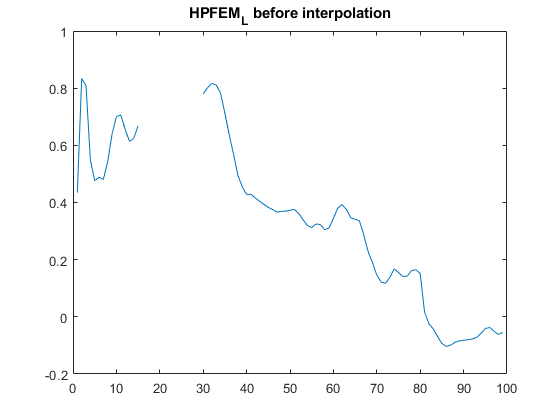

%creating a copy of our dataset for interpolation, which will be the latest dataset that we will work on later on

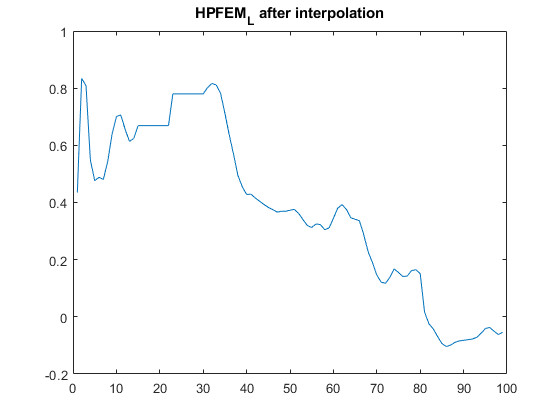

filledData_3 = organizedData_3;

patternNames_3 = ["POBLI_R" "POBLI_L" "PTILT_R" "PTILT_L" "PROTA_R" "PROTA_L" "HPAA_R" "HPAA_L" "HPFE_R" "HPFE_L" ...
    "HPIE_R" "HPIE_L" "KFE_R" "KFE_L" "AFE_R" "AFE_L" "AIE_R" "AIE_L" "HPFEM_R" "HPFEM_L" "KFEM_R" ...

    "KFEM_L" "AFEM_R" "AFEM_L" "HPP_R" "HPP_L" "KP_R" "KP_L" "AP_R" "AP_L" "APF_R" "APF_L" "MLF_R" "MLF_L" "VEF_R" "VEF_L"];
%KIE_R and KIE_L are not included as they were removed

for i_3 = 1:36
    filledData_3{: ,startsWith(string(filledData_3.Properties.VariableNames),patternNames_3(i_3))} = ...
    fillmissing(filledData_3{: ,startsWith(string(filledData_3.Properties.VariableNames),patternNames_3(i_3))},"nearest",2);
end
% the method "nearest" works best here, "linear" seems to be very bad

sumMissingFilledSampleTable_3 = 140×4 table
    id_subject    id_session    id_test    SumMissing
    __________    __________    _______    __________

        1             1            1           0     
        1             1            2           0     
        1             1            3           0     
        2             1            1           0     
        2             1            2           0     
        2             1            3           0     
        3             1            2           0     
        4             1            1           0     
        4             1            2           0     
        4             1            3           0     
        5             1            1           0     
        5             1            2           0     
        5             1            3           0     
        6



%you can compare this visualization with the visualization of post-filling to see if things worked correctly
beginningRow2_3 =37;
endRow2_3 = 37;
PatternToPlot2_3 = "HPFEM_L";
%KIE_R and KIE_L are not included as they were removed

visualization_3=organizedData_3{beginningRow2_3:endRow2_3 ,startsWith(string(organizedData_3.Properties.VariableNames),PatternToPlot2_3)};
plot(1:size(visualization_3,2),visualization_3) %plot of pre-interpolation
title(PatternToPlot2_3 + " before interpolation")

visualizationFilled_3=filledData_3{beginningRow2_3:endRow2_3 ,startsWith(string(filledData_3.Properties.VariableNames),PatternToPlot2_3)};
plot(1:size(visualizationFilled_3,2),visualizationFilled_3) %plot of post-interpolation
title(PatternToPlot2_3 + " after interpolation")



%furthermore, we can count the number of NaNs after interpolation
missingFilled_3 = ismissing(filledData_3);
sumMissingFilledSample_3 = sum(missingFilled_3,2); %the number of missing values for each sample row
sumMissingFilledSampleTable_3 = table(filledData_3.id_subject,filledData_3.id_session,filledData_3.id_test,sumMissingFilledSample_3);
sumMissingFilledSampleTable_3.Properties.VariableNames = {'id_subject','id_session','id_test','SumMissing'}

%it is evident that some samples still have 99 missing values:
% samples 61(26.1.2) and 62(26.1.4) in which "AIE_R" is missing and 49(21.1.2) and 50(21.1.3) in which "HPIE_L" is missing
% so they are removed in the next section

sumMissingFilledSampleTable_3 = 136×4 table
    id_subject    id_session    id_test    SumMissing
    __________    __________    _______    __________

        1             1            1           0     
        1             1            2           0     
        1             1            3           0     
        2             1            1           0     
        2             1            2           0     
        2             1            3           0     
        3             1            2           0     
        4             1            1           0     
        4             1            2           0     
        4             1            3           0     
        5             1            1           0     
        5             1            2           0     
        5             1            3           0     
        6

further removing of incomplete samples

(remember these samples can be added back if the corresponding variables are not used in the final algorithm)

%as these removals are done after interpolation, they are removed from the "filledData_3" as it is our most final dataset up until this point

%removing 26.1.2 as its "AIE_R" is missing 
filledData_3(filledData_3.id_subject == 26 & filledData_3.id_session == 1 & filledData_3.id_test == 2, :) = [];

%removing 26.1.4 as its "AIE_R" is missing 
filledData_3(filledData_3.id_subject == 26 & filledData_3.id_session == 1 & filledData_3.id_test == 4, :) = [];

%removing 21.1.2 as its "HPIE_L" is missing 
filledData_3(filledData_3.id_subject == 21 & filledData_3.id_session == 1 & filledData_3.id_test == 2, :) = [];

%removing 21.1.3 as its "HPIE_L" is missing 
filledData_3(filledData_3.id_subject == 21 & filledData_3.id_session == 1 & filledData_3.id_test == 3, :) = [];



%furthermore, we can count the number of NaNs after removals, which shows there are no NaNs anymore
missingFilled_3 = ismissing(filledData_3);
sumMissingFilledSample_3 = sum(missingFilled_3,2); %the number of missing values for each sample row
sumMissingFilledSampleTable_3 = table(filledData_3.id_subject,filledData_3.id_session,filledData_3.id_test,sumMissingFilledSample_3);
sumMissingFilledSampleTable_3.Properties.VariableNames = {'id_subject','id_session','id_test','SumMissing'}


THIS FILE SEEMS TO BE FINE, NO NEED FOR REPORT PDFS

(BEFORE joining datasets in the end, make sure variables have the same scale , e.g. height)

## PreProcessing organizedData_4, "PoliGaitDatabase_FC ELITE"

organizedData_4;
%first we investigate each variable in the excel files to find irregularities and missing values

### Data Exploration (remove/fix)

dropping the 1st and 101st datapoints in all the signals as they are mostly NaN values and offer little predictive power

VariableNamesString_4 = string(organizedData_4.Properties.VariableNames);
varsToRemove_logical_4 = endsWith(VariableNamesString_4,["R1","L1","R101","L101"]);
varsToRemove_1and101_4 =  VariableNamesString_4(varsToRemove_logical_4);

organizedData_4 = removevars(organizedData_4,varsToRemove_1and101_4);

removing some curropted samples (remember, if the final algorithm does not use some specific features, some of the removed files here can be added back to the dataset)

%removing 3.1.2 as it has a lot of missing values (kinematic, kinetic)
organizedData_4(organizedData_4.id_subject == 3 & organizedData_4.id_session == 1 & organizedData_4.id_test == 2, :) = [];

%removing 3.2.1 as it has a lot of missing values (kinematic, kinetic)
organizedData_4(organizedData_4.id_subject == 3 & organizedData_4.id_session == 2 & organizedData_4.id_test == 1, :) = [];

%removing 3.2.2 as it has a lot of missing values (kinematic, kinetic)
organizedData_4(organizedData_4.id_subject == 3 & organizedData_4.id_session == 2 & organizedData_4.id_test == 2, :) = [];

%removing 4.1.1 as it has a lot of missing values (kinematic)
organizedData_4(organizedData_4.id_subject == 4 & organizedData_4.id_session == 1 & organizedData_4.id_test == 1, :) = [];

%removing 4.2.2 as it has a lot of missing values (kinematic, GRF)
organizedData_4(organizedData_4.id_subject == 4 & organizedData_4.id_session == 2 & organizedData_4.id_test == 2, :) = [];

%removing 5.2.2 as it has a lot of missing values (kinetic, GRF)
organizedData_4(organizedData_4.id_subject == 5 & organizedData_4.id_session == 2 & organizedData_4.id_test == 2, :) = [];

%removing 5.2.3 as it has a lot of missing values (kinetic, GRF)
organizedData_4(organizedData_4.id_subject == 5 & organizedData_4.id_session == 2 & organizedData_4.id_test == 3, :) = [];

%removing 7.2.1 as it has a lot of missing values (kinematic, kinetic, GRF)
organizedData_4(organizedData_4.id_subject == 7 & organizedData_4.id_session == 2 & organizedData_4.id_test == 1, :) = [];

%removing 7.2.2 as it has a lot of missing values (kinematic)
organizedData_4(organizedData_4.id_subject == 7 & organizedData_4.id_session == 2 & organizedData_4.id_test == 2, :) = [];

%removing 8.2.1 as it has a lot of missing values (kinetic, GRF)
organizedData_4(organizedData_4.id_subject == 8 & organizedData_4.id_session == 2 & organizedData_4.id_test == 1, :) = [];

%removing 8.2.3 as it has a lot of missing values (kinetic, GRF)
organizedData_4(organizedData_4.id_subject == 8 & organizedData_4.id_session == 2 & organizedData_4.id_test == 3, :) = [];

%removing 12.2.2 as it has a lot of missing values (kinematic, kinetic)
organizedData_4(organizedData_4.id_subject == 12 & organizedData_4.id_session == 2 & organizedData_4.id_test == 2, :) = [];

%removing 13.1.1 as it has a lot of missing values (GRF)
organizedData_4(organizedData_4.id_subject == 13 & organizedData_4.id_session == 1 & organizedData_4.id_test == 1, :) = [];

%removing 15.2.1 as it has a lot of missing values (kinematic, kinetic)
organizedData_4(organizedData_4.id_subject == 15 & organizedData_4.id_session == 2 & organizedData_4.id_test == 1, :) = [];

%removing 17.2.2 as it has a lot of missing values (kinematic, kinetic)
organizedData_4(organizedData_4.id_subject == 17 & organizedData_4.id_session == 2 & organizedData_4.id_test == 2, :) = [];

%removing 19.2.1 as it has a lot of missing values (GRF)
organizedData_4(organizedData_4.id_subject == 19 & organizedData_4.id_session == 2 & organizedData_4.id_test == 1, :) = [];

%removing 21.2.2 as it has a lot of missing values (kinematic, kinetic)
organizedData_4(organizedData_4.id_subject == 21 & organizedData_4.id_session == 2 & organizedData_4.id_test == 2, :) = [];

%removing 24.2.1 as it has a lot of missing values (kinematic, kinetic)
organizedData_4(organizedData_4.id_subject == 24 & organizedData_4.id_session == 2 & organizedData_4.id_test == 1, :) = [];

%removing 25.2.2 as it has a lot of missing values (kinetic)
organizedData_4(organizedData_4.id_subject == 25 & organizedData_4.id_session == 2 & organizedData_4.id_test == 2, :) = [];

%removing 26.2.2 as it has a lot of missing values (kinematic, kinetic)
organizedData_4(organizedData_4.id_subject == 26 & organizedData_4.id_session == 2 & organizedData_4.id_test == 2, :) = [];

%removing 27.1.1 as it has a lot of missing values (kinematic, kinetic)
organizedData_4(organizedData_4.id_subject == 27 & organizedData_4.id_session == 1 & organizedData_4.id_test == 1, :) = [];

%removing 28.2.1 as it has a lot of missing values (kinematic, kinetic)
organizedData_4(organizedData_4.id_subject == 28 & organizedData_4.id_session == 2 & organizedData_4.id_test == 1, :) = [];


further removal of samples where AFE and MLF are missing (if these are not used in the final algorithm, these samples can be brought back to the dataset)

%removing 1.1.1 as it has a lot of missing values (AFE)
organizedData_4(organizedData_4.id_subject == 1 & organizedData_4.id_session == 1 & organizedData_4.id_test == 1, :) = [];

%removing 1.1.2 as it has a lot of missing values (AFE)
organizedData_4(organizedData_4.id_subject == 1 & organizedData_4.id_session == 1 & organizedData_4.id_test == 2, :) = [];

%removing 1.2.1 as it has a lot of missing values (AFE)
organizedData_4(organizedData_4.id_subject == 1 & organizedData_4.id_session == 2 & organizedData_4.id_test == 1, :) = [];

%removing 1.2.2 as it has a lot of missing values (AFE)
organizedData_4(organizedData_4.id_subject == 1 & organizedData_4.id_session == 2 & organizedData_4.id_test == 2, :) = [];

%removing 2.1.1 as it has a lot of missing values (AFE, MLF)
organizedData_4(organizedData_4.id_subject == 2 & organizedData_4.id_session == 1 & organizedData_4.id_test == 1, :) = [];

%removing 2.1.2 as it has a lot of missing values (AFE, MLF)
organizedData_4(organizedData_4.id_subject == 2 & organizedData_4.id_session == 1 & organizedData_4.id_test == 2, :) = [];

%removing 2.2.1 as it has a lot of missing values (AFE, MLF)
organizedData_4(organizedData_4.id_subject == 2 & organizedData_4.id_session == 2 & organizedData_4.id_test == 1, :) = [];

%removing 2.2.2 as it has a lot of missing values (AFE, MLF)
organizedData_4(organizedData_4.id_subject == 2 & organizedData_4.id_session == 2 & organizedData_4.id_test == 2, :) = [];

%removing 3.1.1 as it has a lot of missing values (AFE)
organizedData_4(organizedData_4.id_subject == 3 & organizedData_4.id_session == 1 & organizedData_4.id_test == 1, :) = [];

%removing 4.2.1 as it has a lot of missing values (AFE)
organizedData_4(organizedData_4.id_subject == 4 & organizedData_4.id_session == 2 & organizedData_4.id_test == 1, :) = [];

%removing 5.1.1 as it has a lot of missing values (AFE)
organizedData_4(organizedData_4.id_subject == 5 & organizedData_4.id_session == 1 & organizedData_4.id_test == 1, :) = [];

%removing 5.1.3 as it has a lot of missing values (AFE)
organizedData_4(organizedData_4.id_subject == 5 & organizedData_4.id_session == 1 & organizedData_4.id_test == 3, :) = [];

%removing 7.2.3 as it has a lot of missing values (AFE)
organizedData_4(organizedData_4.id_subject == 7 & organizedData_4.id_session == 2 & organizedData_4.id_test == 3, :) = [];

%removing 25.2.2 as it has a lot of missing values (AFE, AIE)
organizedData_4(organizedData_4.id_subject == 25 & organizedData_4.id_session == 2 & organizedData_4.id_test == 2, :) = [];

%removing 35.2.2 as it has a lot of missing values (AFE, AIE)
organizedData_4(organizedData_4.id_subject == 35 & organizedData_4.id_session == 2 & organizedData_4.id_test == 2, :) = [];


there are a lot of missing values in KIE as well, but since this variable had the same problem in dataset3 and was removed, it has to be removed from all datasets, so we dont consider this variable one by one and they are all removed

further fixes by interactively looking at table variables in the output panel of matlab, to see distributions and histograms to identify possible outliers and missing values (remember some sections including this one should be run only once, otherwise the operations will be applied multiple times)

%in the double_support_R variable, we have some missing values that are replaced by the average of this variable
organizedData_4.double_support_R = fillmissing(organizedData_4.double_support_R,"constant",mean(organizedData_4.double_support_R,'omitnan'));

%in the double_support_L variable, we have some missing values that are replaced by the average of this variable
organizedData_4.double_support_L = fillmissing(organizedData_4.double_support_L,"constant",mean(organizedData_4.double_support_L,'omitnan'));


organizedData_4 = 148×3786 table
    id_subject    id_session    id_test     note      sex    Age    weight    height    System    speed    cadence    cycle_time_R    cycle_time_L    stance_R    stance_L    swing_R    swing_L    double_support_R    double_support_L    stride_length_R    stride_length_L    step_length_R    step_length_L    step_width    POBLI_R2    POBLI_R3    POBLI_R4    POBLI_R5    POBLI_R6     POBLI_R7    POBLI_R8    POBLI_R9     

up to the end of spaciotemporal is fixed now.

However, the values of them are not compared to report pdfs to see if they are correct (because kinematic,kinetic,grf data are not always similar to pdf reports in dataset_1)

(attention: this section is written after visualization analysis of the next section)

replacing incorrect zeros with NaN

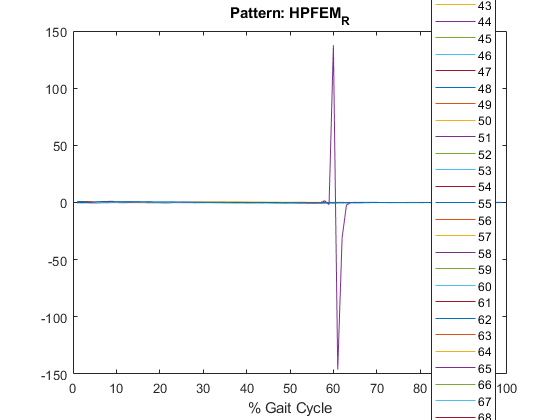

%we can see a lot of missplaced zeros in the graphs, it is evident that some NaNs where replaced with zeros in the original dataset, we need to replace them with NaN again and interpolate later on (except for GRF data that naturally has a lot of zeros in the second half)

%first, we need to define kinematic and kinetic parts of dataset to replace their zeros (even if some zeros are true zeros, they will be derived again in the interpolation process in the coming sections)
allPatternsExceptGRF_4 = ["POBLI_R" "POBLI_L" "PTILT_R" "PTILT_L" "PROTA_R" "PROTA_L" "HPAA_R" "HPAA_L" "HPFE_R" "HPFE_L" ...
    "HPIE_R" "HPIE_L" "KFE_R" "KFE_L" "KIE_R" "KIE_L" "AFE_R" "AFE_L" "AIE_R" "AIE_L" "HPFEM_R" "HPFEM_L" "KFEM_R" ...
    "KFEM_L" "AFEM_R" "AFEM_L" "HPP_R" "HPP_L" "KP_R" "KP_L" "AP_R" "AP_L"];

%now we replace zeros with NaN
organizedData_4(:,startsWith(string(organizedData_4.Properties.VariableNames),allPatternsExceptGRF_4)) = ...
    standardizeMissing(organizedData_4(:,startsWith(string(organizedData_4.Properties.VariableNames),allPatternsExceptGRF_4)),[NaN 0]);

%by rerunning the visualizations in the next section we can see that inconsistencies of zeros are gone

organizedData_4

### Visualization

further fixes by Visualization (kinematics, kinetics, GRF)

- `tests of the same subject are rows of:`

- `    1:2 for subject5`

- `    3:7 for subject6`

- `    8:8 for subject7`

- `    9:14 for subject8`

- `    15:20 for subject9`

- `    21:26 for subject10`

- `        .`

- `        .`

- `        .`

- `        .`

- `        .`

- `    (40 subjects!)`

- `this is not true after the next sections are ran, as some samples are removed in the next sections, the row number for tests will become different`

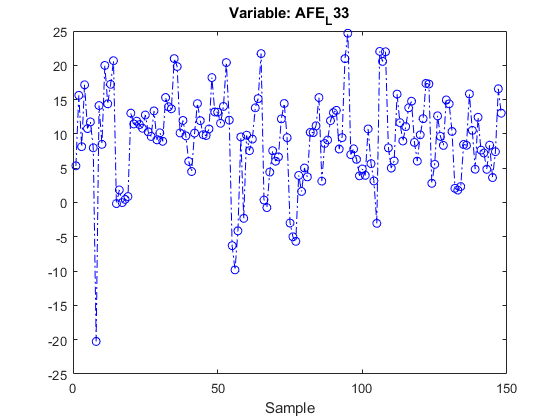

%visualizing kinematic, kinetic and GRF patterns to find weird stuff
%change the three variables below for visualizations of interest
%try to visualize different patterns by superimposing all/uni-subject samples to find outliers
%try to compare righ/left sides of the same patterns
beginningRow1_4 =41;
endRow1_4 = 69;
PatternToPlot1_4 = "HPFEM_R";

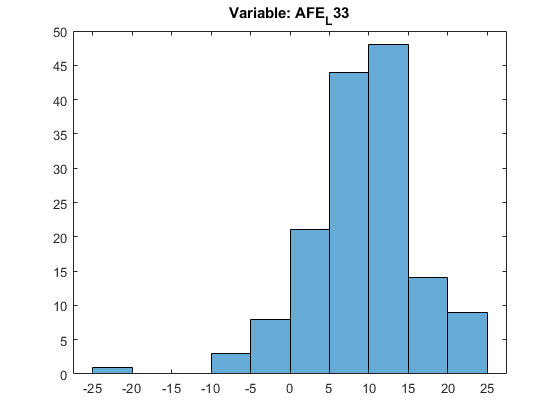




visualization_4=organizedData_4{beginningRow1_4:endRow1_4 ,startsWith(string(organizedData_4.Properties.VariableNames),PatternToPlot1_4)};

plot(1:size(visualization_4,2),visualization_4)
title("Pattern: "+PatternToPlot1_4)
xlabel("% Gait Cycle")
legend(string(beginningRow1_4:endRow1_4),"Location","best")

%remember in the final algorithm, it might be a good idea to use only the first half of GRF data in all datasets, as the second half is inconsistent and mostly zeros

%samples 8(7.1.1), 35(12.2.1), 38(13.2.2), 40(14.1.1), 58(18.1.1), 70(20.2.3), 74(21.2.1), 96(28.1.1),...
%...101(29.2.1), 103(30.1.2), 104(30.1.3), 112(31.2.1), 113(32.1.1), 126(36.1.1), 127(36.1.2), 130(36.2.2), 132(37.1.1), 139(38.1.3), 140(38.2.1), 141(39.1.1), 143(39.2.1), 144(40.1.1), 146(40.1.3), 147(40.2.1), 148(40.2.2) look like outliers ...
%...they are removed in the next sections(they might actually be able to explain the target variable, if so you need to add them back)

%from samples 100 onwards there are a lot of weird samples, they might either be able to explain the target or be outliers, nothing has been done about these samples yet

after running next sections, 25 samples will be removed, so the number of samples will reduce from 148 to 123 and the plotting might encounter errors, this can be avoided by putting the endRow variable at a maximum of 123 instead of 148.

remember the sample numbers (e.g. 122) do NOT correspond to the same tests now, always try to double-check when you are trying to find the specific test from the sample number, by generating a brand new table at the specific lines of code. Clearing and rerunning the script section by section can help to avoid problems.

further fixes by Visualization (variables)

%this can help finding samples that have weird values for each variable (finding outliers)
%as long as observations belonging to the same subject have similar values, things are fine

VariableToPlot_4 = 'AFE_L33';



plot(organizedData_4{:,VariableToPlot_4},"bo-.")
title("Variable: "+VariableToPlot_4)
xlabel("Sample")


histogram(organizedData_4{:,VariableToPlot_4})
title("Variable: "+VariableToPlot_4)



%similar results as in the previous section, so they will be removed in the next section 

rerunning this section after next section is ran will give us different plots, as some samples (outliers) will be removed

further removing of curropt samples

%removing 7.1.1 as it looks like an outlier 
organizedData_4(organizedData_4.id_subject == 7 & organizedData_4.id_session == 1 & organizedData_4.id_test == 1, :) = [];

%removing 12.2.1 as it looks like an outlier 
organizedData_4(organizedData_4.id_subject == 12 & organizedData_4.id_session == 2 & organizedData_4.id_test == 1, :) = [];

%removing 13.2.2 as it looks like an outlier 
organizedData_4(organizedData_4.id_subject == 13 & organizedData_4.id_session == 2 & organizedData_4.id_test == 2, :) = [];

%removing 14.1.1 as it looks like an outlier 
organizedData_4(organizedData_4.id_subject == 14 & organizedData_4.id_session == 1 & organizedData_4.id_test == 1, :) = [];

%removing 18.1.1 as it looks like an outlier 
organizedData_4(organizedData_4.id_subject == 18 & organizedData_4.id_session == 1 & organizedData_4.id_test == 1, :) = [];

%removing 20.2.3 as it looks like an outlier 
organizedData_4(organizedData_4.id_subject == 20 & organizedData_4.id_session == 2 & organizedData_4.id_test == 3, :) = [];

%removing 21.2.1 as it looks like an outlier 
organizedData_4(organizedData_4.id_subject == 21 & organizedData_4.id_session == 2 & organizedData_4.id_test == 1, :) = [];

%removing 28.1.1 as it looks like an outlier 
organizedData_4(organizedData_4.id_subject == 28 & organizedData_4.id_session == 1 & organizedData_4.id_test == 1, :) = [];

%removing 29.2.1 as it looks like an outlier 
organizedData_4(organizedData_4.id_subject == 29 & organizedData_4.id_session == 2 & organizedData_4.id_test == 1, :) = [];

%removing 30.1.2 as it looks like an outlier 
organizedData_4(organizedData_4.id_subject == 30 & organizedData_4.id_session == 1 & organizedData_4.id_test == 2, :) = [];

%removing 30.1.3 as it looks like an outlier 
organizedData_4(organizedData_4.id_subject == 30 & organizedData_4.id_session == 1 & organizedData_4.id_test == 3, :) = [];

%removing 31.2.1 as it looks like an outlier 
organizedData_4(organizedData_4.id_subject == 31 & organizedData_4.id_session == 2 & organizedData_4.id_test == 1, :) = [];

%removing 32.1.1 as it looks like an outlier 
organizedData_4(organizedData_4.id_subject == 32 & organizedData_4.id_session == 1 & organizedData_4.id_test == 1, :) = [];

%removing 36.1.1 as it looks like an outlier 
organizedData_4(organizedData_4.id_subject == 36 & organizedData_4.id_session == 1 & organizedData_4.id_test == 1, :) = [];

%removing 36.1.2 as it looks like an outlier 
organizedData_4(organizedData_4.id_subject == 36 & organizedData_4.id_session == 1 & organizedData_4.id_test == 2, :) = [];

%removing 36.2.2 as it looks like an outlier 
organizedData_4(organizedData_4.id_subject == 36 & organizedData_4.id_session == 2 & organizedData_4.id_test == 2, :) = [];

%removing 37.1.1 as it looks like an outlier 
organizedData_4(organizedData_4.id_subject == 37 & organizedData_4.id_session == 1 & organizedData_4.id_test == 1, :) = [];

%removing 38.1.3 as it looks like an outlier 
organizedData_4(organizedData_4.id_subject == 38 & organizedData_4.id_session == 1 & organizedData_4.id_test == 3, :) = [];

%removing 38.2.1 as it looks like an outlier 
organizedData_4(organizedData_4.id_subject == 38 & organizedData_4.id_session == 2 & organizedData_4.id_test == 1, :) = [];

%removing 39.1.1 as it looks like an outlier 
organizedData_4(organizedData_4.id_subject == 39 & organizedData_4.id_session == 1 & organizedData_4.id_test == 1, :) = [];

sumMissingVariableTable_4 = 1×3786 table
    id_subject_SumMissing    id_session_SumMissing    id_test_SumMissing    note_SumMissing    sex_SumMissing    Age_SumMissing    weight_SumMissing    height_SumMissing    System_SumMissing    speed_SumMissing    cadence_SumMissing    cycle_time_R_SumMissing    cycle_time_L_SumMissing    stance_R_SumMissing    stance_L_SumMissing    swing_R_SumMissing    swing_L_SumMissing    double_support_R_SumMissing    double_support_L_SumMissing    stride_length_R_SumMissing    stride_length_L_SumMissing    step_length_R_SumMissing    step_length_L_SumMissing    st


%removing 39.2.1 as it looks like an outlier 
organizedData_4(organizedData_4.id_subject == 39 & organizedData_4.id_session == 2 & organizedData_4.id_test == 1, :) = [];

%removing 40.1.1 as it looks like an outlier 
organizedData_4(organizedData_4.id_subject == 40 & organizedData_4.id_session == 1 & organizedData_4.id_test == 1, :) = [];

%removing 40.1.3 as it looks like an outlier 
organizedData_4(organizedData_4.id_subject == 40 & organizedData_4.id_session == 1 & organizedData_4.id_test == 3, :) = [];

sumMissingSampleTable_4 = 123×4 table
    id_subject    id_session    id_test    SumMissing
    __________    __________    _______    __________

        5             1            2          140    
        5             2            1           67    
        6             1            1           39    
        6             1            2           27    
        6             1            3           50    
        6             2            1           37    
        6             2            2           42    
        8             1            1            6    
        8             1            2           54    
        8             1            3           11    
        8             1            4            0    
        8             2            2           27    
        8             2            4           52    
        9      


%removing 40.2.1 as it looks like an outlier 
organizedData_4(organizedData_4.id_subject == 40 & organizedData_4.id_session == 2 & organizedData_4.id_test == 1, :) = [];

%removing 40.2.2 as it looks like an outlier 
organizedData_4(organizedData_4.id_subject == 40 & organizedData_4.id_session == 2 & organizedData_4.id_test == 2, :) = [];


%now we there are 123 samples in this dataset

### Handling Missing Data

Finding missing values

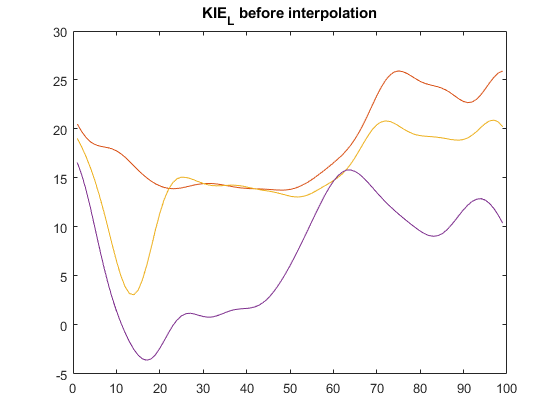

organizedData_4;
missing_4 = ismissing(organizedData_4); %all missing values



sumMissingVariable_4 = sum(missing_4,1); %the number of missing values for each variable column
sumMissingVariableTable_4 = cell2table(cellstr(string(sumMissingVariable_4)));
sumMissingVariableTable_4.Properties.VariableNames = organizedData_4.Properties.VariableNames + "_SumMissing"
%based on this table, it might be a good idea to remove the variables that have a lot of missing values
%for now we will use interpolation for each pattern to preserve more variables in the dataset
%since the table is too wide, the following code can be used to find the variable with highest number of missing values >
% > [m,idx]=max(sumMissingVariable_4) > sumMissingVariableTable_4(1,idx) % so this variable can be removed



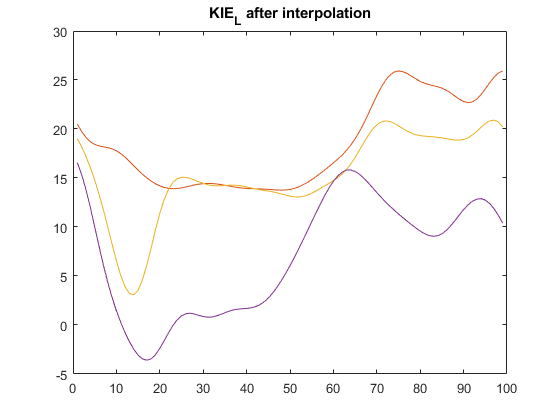

sumMissingSample_4 = sum(missing_4,2); %the number of missing values for each sample row
sumMissingSampleTable_4 = table(organizedData_4.id_subject,organizedData_4.id_session,organizedData_4.id_test,sumMissingSample_4);
sumMissingSampleTable_4.Properties.VariableNames = {'id_subject','id_session','id_test','SumMissing'}
%based on this table, it might be a good idea to remove the samples that have a lot of missing values

%for now we will use interpolation for each pattern to preserve more samples in the dataset

maybe the samples that have too many NaNs on the edges of their patterns should be removed here if the interpolation of the next section doesnt work on them well. check it if the final algorithm does not work well

Handling missing values (the methods used for interpolation in this section can be modified later to acquire better results)

%creating a copy of our dataset for interpolation, which will be the latest dataset that we will work on later on
filledData_4 = organizedData_4;

patternNames_4 = ["POBLI_R" "POBLI_L" "PTILT_R" "PTILT_L" "PROTA_R" "PROTA_L" "HPAA_R" "HPAA_L" "HPFE_R" "HPFE_L" ...

sumMissingFilledSampleTable_4 = 123×4 table
    id_subject    id_session    id_test    SumMissing
    __________    __________    _______    __________

        5             1            2           0     
        5             2            1           0     
        6             1            1           0     
        6             1            2           0     
        6             1            3           0     
        6             2            1           0     
        6             2            2           0     
        8             1            1           0     
        8             1            2           0     
        8             1            3           0     
        8             1            4           0     
        8             2            2           0     
        8             2            4           0     
        9

    "HPIE_R" "HPIE_L" "KFE_R" "KFE_L" "KIE_R" "KIE_L" "AFE_R" "AFE_L" "AIE_R" "AIE_L" "HPFEM_R" "HPFEM_L" "KFEM_R" ...
    "KFEM_L" "AFEM_R" "AFEM_L" "HPP_R" "HPP_L" "KP_R" "KP_L" "AP_R" "AP_L" "APF_R" "APF_L" "MLF_R" "MLF_L" "VEF_R" "VEF_L"];

for i_4 = 1:38
    filledData_4{: ,startsWith(string(filledData_4.Properties.VariableNames),patternNames_4(i_4))} = ...
    fillmissing(filledData_4{: ,startsWith(string(filledData_4.Properties.VariableNames),patternNames_4(i_4))},"nearest",2);
end
% the method "nearest" works best here, "linear" seems to be very bad


%you can compare this visualization with the visualization of post-filling to see if things worked correctly
beginningRow2_4 =68;
endRow2_4 = 72;
PatternToPlot2_4 = "KIE_L";
visualization_4=organizedData_4{beginningRow2_4:endRow2_4 ,startsWith(string(organizedData_4.Properties.VariableNames),PatternToPlot2_4)};
plot(1:size(visualization_4,2),visualization_4) %plot of pre-interpolation
title(PatternToPlot2_4 + " before interpolation")

visualizationFilled_4=filledData_4{beginningRow2_4:endRow2_4 ,startsWith(string(filledData_4.Properties.VariableNames),PatternToPlot2_4)};
plot(1:size(visualizationFilled_4,2),visualizationFilled_4) %plot of post-interpolation
title(PatternToPlot2_4 + " after interpolation")



%furthermore, we can count the number of NaNs after interpolation, which shows there are only 2 samples with NaNs remaining (related to missing KIE which will be remove before concatenation of datasets, so no worries)
missingFilled_4 = ismissing(filledData_4);
sumMissingFilledSample_4 = sum(missingFilled_4,2); %the number of missing values for each sample row
sumMissingFilledSampleTable_4 = table(filledData_4.id_subject,filledData_4.id_session,filledData_4.id_test,sumMissingFilledSample_4);
sumMissingFilledSampleTable_4.Properties.VariableNames = {'id_subject','id_session','id_test','SumMissing'}


THIS FILE SEEMS TO BE FINE, NO NEED FOR REPORT PDFS

## Combining All Datasets for Other Common PreProcessing

clearing the workspace to keep only the 4 final datasets

clearvars -except filledData_1 filledData_2 filledData_3 filledData_4

removal of KIE_R and KIE_L variables, as they are all missing in the 3rd dataset, so they have to be removed from the others so that they will have the same size (knee rotation does not provide much information anyway)

filledData_1(:, startsWith(string(filledData_1.Properties.VariableNames),'KIE')) = [];

filledData_2(:, startsWith(string(filledData_2.Properties.VariableNames),'KIE')) = [];

filledData_4(:, startsWith(string(filledData_4.Properties.VariableNames),'KIE')) = [];

%now all of the datasets have the same number of variables

interactive inspection of the datasets to make sure the variables follow the same scale and distribution before concatenation

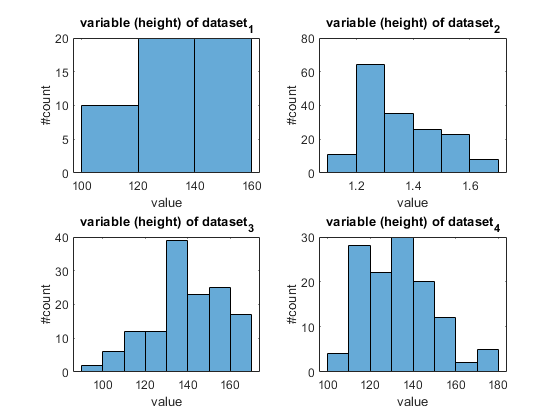

%choose the variable of interest to inspect the histogram and its scale
histogramToPlot = 'height';


subplot(2,2,1)
histogram(filledData_1{:,histogramToPlot})
title("variable (" + histogramToPlot + ") of dataset_1")
ylabel('#count')
xlabel('value')

subplot(2,2,2)
histogram(filledData_2{:,histogramToPlot})
title("variable (" + histogramToPlot + ") of dataset_2")
ylabel('#count')
xlabel('value')

subplot(2,2,3)
histogram(filledData_3{:,histogramToPlot})
title("variable (" + histogramToPlot + ") of dataset_3")
ylabel('#count')
xlabel('value')

subplot(2,2,4)
histogram(filledData_4{:,histogramToPlot})

filledData_all = 476×3588 table
    id_subject    id_session    id_test     note      sex    Age    weight    height    System    speed    cadence    cycle_time_R    cycle_time_L    stance_R    stance_L    swing_R    swing_L    double_support_R    double_support_L    stride_length_R    stride_length_L    step_length_R    step_length_L    step_width    POBLI_R2    POBLI_R3    POBLI_R4    POBLI_R5    POBLI_R6    POBLI_R7    POBLI_R8    POBLI_R9    

title("variable (" + histogramToPlot + ") of dataset_4")
ylabel('#count')

filledData_234 = 426×3588 table
    id_subject    id_session    id_test     note      sex    Age    weight    height    System    speed    cadence    cycle_time_R    cycle_time_L    stance_R    stance_L    swing_R    swing_L    double_support_R    double_support_L    stride_length_R    stride_length_L    step_length_R    step_length_L    step_width    POBLI_R2    POBLI_R3    POBLI_R4    POBLI_R5    POBLI_R6    POBLI_R7    POBLI_R8    POBLI_R9    

xlabel('value')

clf %clears the figure window that we used for subplotting, so that next plots won't encounter problems

%variable (height) of dataset2 should be multiplied by 100 to have the same scale as the others, it is done in the next section
%dataset1 patterns seems to be messy, it might be a good idea to either fix it or remove it completely (if the used variables at the end of algorithm show consistency in dataset1, we can use this dataset)

fixing variable (height) of dataset2 (remember this section should not be ran more than once, otherwise it will repeat the calculations and it will lead to incorrect data), BE CAREFULL

filledData_2.height = filledData_2.height * 100;

changing the subject_id of the datasets as they overlap after concatenation (this section should be ran only once)

filledData_2.id_subject = filledData_2.id_subject + filledData_1.id_subject(end);
filledData_3.id_subject = filledData_3.id_subject + filledData_2.id_subject(end);
filledData_4.id_subject = filledData_4.id_subject + filledData_3.id_subject(end);

%dataset1 : subjects 1:9
%dataset2 : subjects 10:28
%dataset3 : subjects 29:88
%dataset4 : subjects 89:128

concatenating the datasets

filledData_all = [filledData_1 ; filledData_2 ; filledData_3 ; filledData_4]

filledData_234 = [filledData_2 ; filledData_3 ; filledData_4]
%dataset1 patterns seem to be messy, it might be a good idea to either fix it or remove it completely (if the used variables at the end of algorithm show consistency in dataset1, we can use this dataset)

%dataset1 : subjects 1:9
%dataset2 : subjects 10:28
%dataset3 : subjects 29:88
%dataset4 : subjects 89:128

now, we work with the reduced dataset. In the end, we can use the complete dataset to see if it works well

## Feature Engineering 

(adding new features by visualizations of the next section) (IF YOU ADD SOMETHING NEW REMEMBER TO NORMALIZE IT)

this is done right before visualization section, so that the new features can be visualized too see if they are good enough

%R/L ratio of spaciotemporal features

filledData_234.cycle_time_division = filledData_234.cycle_time_R ./ filledData_234.cycle_time_L;
filledData_234.stance_division = filledData_234.stance_R ./ filledData_234.stance_L;
filledData_234.swing_division = filledData_234.swing_R ./ filledData_234.swing_L;
filledData_234.double_support_division = filledData_234.double_support_R ./ filledData_234.double_support_L;
filledData_234.stride_length_division = filledData_234.stride_length_R ./ filledData_234.stride_length_L;
filledData_234.step_length_division = filledData_234.step_length_R ./ filledData_234.step_length_L;



filledData_234 = 426×3604 table
    id_subject    id_session    id_test     note      sex    Age    weight    height    System    speed    cadence    cycle_time_R    cycle_time_L    stance_R    stance_L    swing_R    swing_L    double_support_R    double_support_L    stride_length_R    stride_length_L    step_length_R    step_length_L    step_width    POBLI_R2    POBLI_R3    POBLI_R4    POBLI_R5    POBLI_R6    POBLI_R7    POBLI_R8    POBLI_R9    

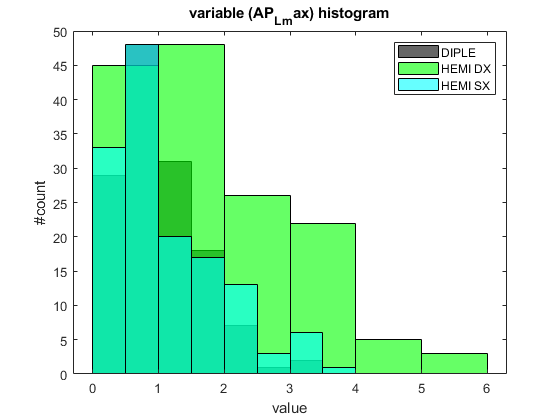




%feature extraction from patterns

%mean was also derived, but median is less sensitive to outliers + R/L division is not good since most of them become zero or one
%these are good features to create as there is a noticable shift in the patterns of different classes
%many features were derived from other patterns as well, but they were not statistically significant, so their code was removed

filledData_234.PROTA_R_median = median(filledData_234{:,startsWith(string(filledData_234.Properties.VariableNames),'PROTA_R')},2);
filledData_234.PROTA_L_median = median(filledData_234{:,startsWith(string(filledData_234.Properties.VariableNames),'PROTA_L')},2);

filledData_234.HPFE_R_median = median(filledData_234{:,startsWith(string(filledData_234.Properties.VariableNames),'HPFE_R')},2);
filledData_234.HPFE_L_median = median(filledData_234{:,startsWith(string(filledData_234.Properties.VariableNames),'HPFE_L')},2);

filledData_234.KFE_R_median = median(filledData_234{:,startsWith(string(filledData_234.Properties.VariableNames),'KFE_R')},2);
filledData_234.KFE_L_median = median(filledData_234{:,startsWith(string(filledData_234.Properties.VariableNames),'KFE_L')},2);

filledData_234.HPP_R_min = min(filledData_234{:,startsWith(string(filledData_234.Properties.VariableNames),'HPP_R')},[],2);
filledData_234.HPP_L_min = min(filledData_234{:,startsWith(string(filledData_234.Properties.VariableNames),'HPP_L')},[],2);

filledData_234.AP_R_max = max(filledData_234{:,startsWith(string(filledData_234.Properties.VariableNames),'AP_R')},[],2);
filledData_234.AP_L_max = max(filledData_234{:,startsWith(string(filledData_234.Properties.VariableNames),'AP_L')},[],2)



%filledData_234.HPFE_division_median = filledData_234.HPFE_R_median ./ filledData_234.HPFE_L_median;


## Visualization for Comparison

comparison plots in order to see trends in Hemi DX, Hemi SX and Diple for the reduced dataset

### Histogram and Boxplot

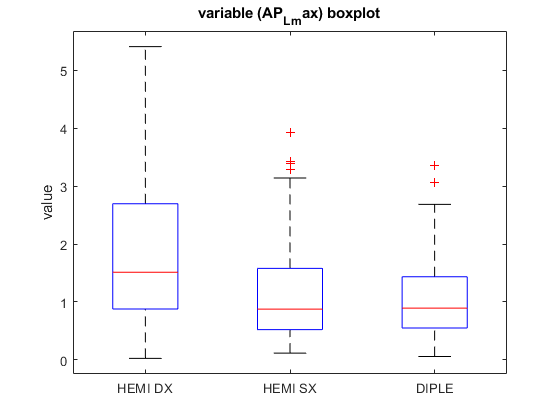

%choose the variable of interest for comparison
histogramToCompare = 'AP_L_max';
%not all variables make sense here, this might lead to errors or insensible graphs, choose the variables that make sense

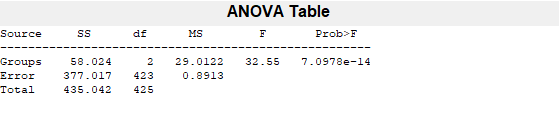

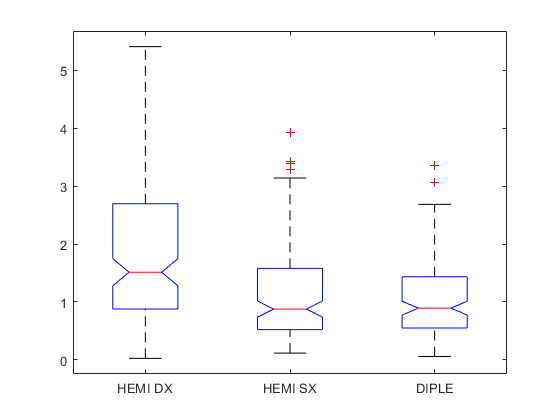

p = 7.0978e-14




histogram(filledData_234{filledData_234.note == "DIPLE" , histogramToCompare},'FaceColor','k')
hold on

histogram(filledData_234{filledData_234.note == "HEMI DX" , histogramToCompare},'FaceColor','g')
histogram(filledData_234{filledData_234.note == "HEMI SX" , histogramToCompare},'FaceColor','c')
title("variable (" + histogramToCompare + ") histogram")
ylabel('#count')
xlabel('value')

grpSummaryFilled = 3×13 table
     note      GroupCount    mean_cycle_time_R    sum_cycle_time_R    min_cycle_time_R    max_cycle_time_R    range_cycle_time_R    median_cycle_time_R    mode_cycle_time_R    var_cycle_time_R    std_cycle_time_R    nummissing_cycle_time_R    nnz_cycle_time_R
    _______    __________    _________________    ________________    ________________    ________________    __________________    ___________________    _________________    ________________    ________________    _______________________    ________________

    HEM

legend('DIPLE','HEMI DX','HEMI SX')
hold off





boxplot(filledData_234{: , histogramToCompare},filledData_234.note)

title("variable (" + histogramToCompare + ") boxplot")
ylabel('value')




p = anova1(filledData_234.(histogramToCompare),filledData_234.note)

### Groupsummary calculations

this can help to explore good explanatory variables for the classification algorithm (it might also help with feature engineering to create new explanatory variables)

grpSummaryFilled = groupsummary(filledData_234,"note","all",'cycle_time_R')
%this calculates statistics for numeric variables grouped by our target variable

this can be done after normalization as well (it will have different results)

### Kinematic, Kinetic and GRF complete patterns 

( this visualization can help with feature engineering to create new explanatory variables)

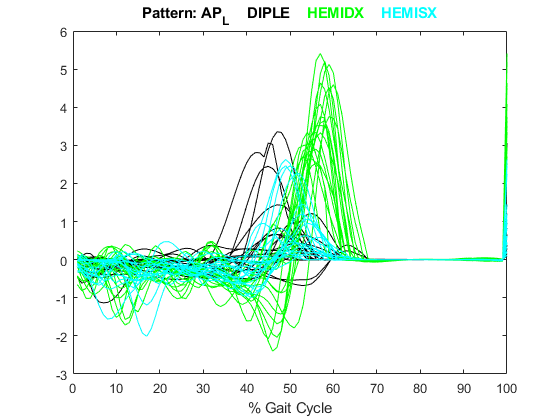

%dividing datasets
DIPLE_DATA = filledData_234(filledData_234.note == "DIPLE",:);
HEMIDX_DATA = filledData_234(filledData_234.note == "HEMI DX",:);
HEMISX_DATA = filledData_234(filledData_234.note == "HEMI SX",:);


beginningRow =47;
endRow = 65; % this is the minimum sample number in the datasets for convenience, some have more samples

PatternToPlot = "AP_L";



visualization_DIPLE=DIPLE_DATA{beginningRow:endRow ,startsWith(string(DIPLE_DATA.Properties.VariableNames),PatternToPlot)};
plot(1:size(visualization_DIPLE,2),visualization_DIPLE,'k')

ans = 12


hold on

visualization_HEMIDX=HEMIDX_DATA{beginningRow:endRow ,startsWith(string(HEMIDX_DATA.Properties.VariableNames),PatternToPlot)};
plot(1:size(visualization_HEMIDX,2),visualization_HEMIDX,'g')

visualization_HEMISX=HEMISX_DATA{beginningRow:endRow ,startsWith(string(HEMISX_DATA.Properties.VariableNames),PatternToPlot)};
plot(1:size(visualization_HEMISX,2),visualization_HEMISX,'c')

hold off

title('Pattern: '+PatternToPlot+'   \color{black} DIPLE'+'   \color{green} HEMIDX'+'   \color{cyan} HEMISX')
xlabel("% Gait Cycle")


## Handling Outliers 

(this has been done manually in the exploratory data analysis sections before, but if further outlier removal is needed you can continue here, refer to coursera 2 week 3)

sum(isoutlier(filledData_234{:,'AP_R_max'})) %number of outliers for a given variable

%filledData_234 = rmoutliers(filledData_234,'percentiles',[0,99.99],'DataVariables','AP_R_max')

## Normalization and Standardization

first, we need to normalize Stride_Length, Step_Length and Step_Width variables with respect to patient's Height (run only once)

filledData_234;
filledData_234.stride_length_R = filledData_234.stride_length_R ./ filledData_234.height;
filledData_234.stride_length_L = filledData_234.stride_length_L ./ filledData_234.height;
filledData_234.step_length_R = filledData_234.step_length_R ./ filledData_234.height;
filledData_234.step_length_L = filledData_234.step_length_L ./ filledData_234.height;

ans = 1×1 cell array
    {'cycle_time_division'}


filledData_234.step_width = filledData_234.step_width ./ filledData_234.height;

normalizedData_234 = 426×3604 table
    id_subject    id_session    id_test     note      sex    Age    weight    height    System    speed    cadence     cycle_time_R    cycle_time_L    stance_R    stance_L    swing_R    swing_L    double_support_R    double_support_L    stride_length_R    stride_length_L    step_length_R    step_length_L    step_width    POBLI_R2    POBLI_R3    POBLI_R4    POBLI_R5    POBLI_R6    POBLI_R7    POBLI_R8    POBLI_R9    <

transforming the range of values in our data to allow direct comparison between variables (it will become important for model training as well since distance measurement is influenced by scale of the variables)

so normalization causes variables to contribute equally in the algorithms that work with numeric distances

filledData_234;

%normalizing spaciotemporal variables (from 10="speed" to 24="step_width")
%normalizing patterns as well (but remember it changes the true shape of the signals, this might not be a good idea to normalize patterns this way, so they have not yet been normalized, you can do it later if the algorithm does not work)
%the method of normalization can be changed later to get better results (considering distribution of data)

ans = 0

normalizedData_234 = normalize(filledData_234(:,10:24),"zscore","robust");

ans = 0


%adding the other variables to the latest dataset that were not considered in normalization
normalizedData_234 = [filledData_234(:,1:9) , normalizedData_234 , filledData_234(:,25:end)];

%normalizing the new features that are added to the end of dataset

ans = 1×1 cell array
    {'APF_R61'}


normalizedData_234.Properties.VariableNames(3589) %making sure the index is correct

ans = 1×1 cell array
    {'APF_R100'}


normalizedData_234(:,3589:end) = normalize(normalizedData_234(:,3589:end),"zscore","robust")

%remember removing outliers beforhand can give better results

ans = 1×1 cell array
    {'APF_L61'}


ans = 1×1 cell array
    {'APF_L100'}


ans = 1×1 cell array
    {'MLF_R61'}


ans = 1×1 cell array
    {'MLF_R100'}


%it appears that after normalization of "patterns" alot of NaNs are introduced to the dataset, they all correspond to the second half of GRF data (they are removed as the GRF of swing phase is supposed to be zero and has no predictive power, they are removed even if normalization is not done on the patterns)
sum(sum(ismissing(filledData_234)))
sum(sum(ismissing(normalizedData_234)))

ans = 1×1 cell array
    {'MLF_L61'}


ans = 1×1 cell array
    {'MLF_L100'}



%removing the swing phase of GRF data (let the code here be in the same section, don't change it)
%be very careful of indices here, they are constantly changing everytime you run a line

ans = 1×1 cell array
    {'VEF_R61'}


normalizedData_234.Properties.VariableNames(3054)

ans = 1×1 cell array
    {'VEF_R100'}


normalizedData_234.Properties.VariableNames(3093)
normalizedData_234(:,3054:3093) = [];


ans = 1×1 cell array
    {'VEF_L61'}


normalizedData_234.Properties.VariableNames(3113)

ans = 1×1 cell array
    {'VEF_L100'}


normalizedData_234.Properties.VariableNames(3152)
normalizedData_234(:,3113:3152) = [];

normalizedData_234.Properties.VariableNames(3172)
normalizedData_234.Properties.VariableNames(3211)

ans = 0

normalizedData_234(:,3172:3211) = [];

ans = 0


normalizedData_234.Properties.VariableNames(3231)
normalizedData_234.Properties.VariableNames(3270)
normalizedData_234(:,3231:3270) = [];

normalizedData_234.Properties.VariableNames(3290)

ans = 1×1 cell array
    {'APF_R61'}


normalizedData_234.Properties.VariableNames(3329)

ans = 1×1 cell array
    {'APF_R100'}


normalizedData_234(:,3290:3329) = [];

normalizedData_234.Properties.VariableNames(3349)

ans = 1×1 cell array
    {'APF_L61'}


normalizedData_234.Properties.VariableNames(3388)

ans = 1×1 cell array
    {'APF_L100'}


normalizedData_234(:,3349:3388) = [];



ans = 1×1 cell array
    {'MLF_R61'}


ans = 1×1 cell array
    {'MLF_R100'}


sum(sum(ismissing(filledData_234)))
sum(sum(ismissing(normalizedData_234)))


ans = 1×1 cell array
    {'MLF_L61'}


ans = 1×1 cell array
    {'MLF_L100'}



%removing the swing phase of GRF data (let the code here be in the same section, don't change it)
%be very careful of indices here, they are constantly changing everytime you run a line

ans = 1×1 cell array
    {'VEF_R61'}


filledData_234.Properties.VariableNames(3054)

ans = 1×1 cell array
    {'VEF_R100'}


filledData_234.Properties.VariableNames(3093)
filledData_234(:,3054:3093) = [];


ans = 1×1 cell array
    {'VEF_L61'}


filledData_234.Properties.VariableNames(3113)

ans = 1×1 cell array
    {'VEF_L100'}


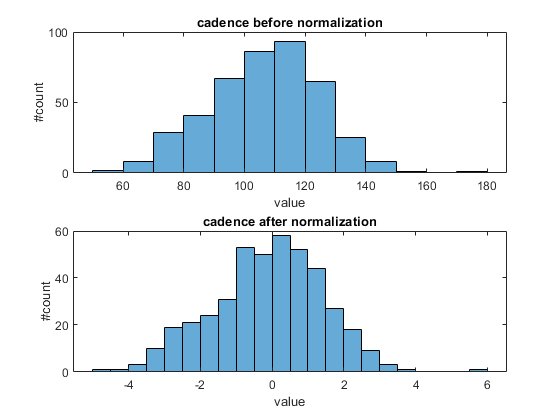

filledData_234.Properties.VariableNames(3152)
filledData_234(:,3113:3152) = [];

filledData_234.Properties.VariableNames(3172)
filledData_234.Properties.VariableNames(3211)
filledData_234(:,3172:3211) = [];

filledData_234.Properties.VariableNames(3231)
filledData_234.Properties.VariableNames(3270)
filledData_234(:,3231:3270) = [];

filledData_234.Properties.VariableNames(3290)
filledData_234.Properties.VariableNames(3329)
filledData_234(:,3290:3329) = [];

filledData_234.Properties.VariableNames(3349)
filledData_234.Properties.VariableNames(3388)

filledData_234(:,3349:3388) = [];

visualizing the histograms before and after normalization

%remember some variables are removed and choosing them will result in error
variable = 'cadence';

subplot(2,1,1)
histogram(filledData_234{:,variable})
title(variable + " before normalization")
ylabel('#count')
xlabel('value')

subplot(2,1,2)
histogram(normalizedData_234{:,variable})
title(variable + " after normalization")
ylabel('#count')
xlabel('value')

clf

Smoothing

(only for indexed data where there is a specific order, as the window works on subsequent data points)

%smoothdata()
%%%normalizedData_234

%creating a copy of our dataset for smoothing, which will be the latest dataset that we will work on later on
%%%smoothedData_234 = normalizedData_234;

%%%patternNames = ["POBLI_R" "POBLI_L" "PTILT_R" "PTILT_L" "PROTA_R" "PROTA_L" "HPAA_R" "HPAA_L" "HPFE_R" "HPFE_L" ...
%%%    "HPIE_R" "HPIE_L" "KFE_R" "KFE_L" "AFE_R" "AFE_L" "AIE_R" "AIE_L" "HPFEM_R" "HPFEM_L" "KFEM_R" ...
%%%    "KFEM_L" "AFEM_R" "AFEM_L" "HPP_R" "HPP_L" "KP_R" "KP_L" "AP_R" "AP_L" "APF_R" "APF_L" "MLF_R" "MLF_L" "VEF_R" "VEF_L"];



%%%for i = 1:36
%%%    smoothedData_234{: ,startsWith(string(smoothedData_234.Properties.VariableNames),patternNames(i))} = ...
%%%    smoothdata(smoothedData_234{: ,startsWith(string(smoothedData_234.Properties.VariableNames),patternNames(i))},2,"movmedian");
%%%end
%the method and window length can be changed later to achieve better results
%smoothing is done on each pattern individually in the loop so that they don't affect each other



%you can compare pre/post smoothing to see if things worked correctly
%%%beginningRow =207;
%%%endRow = 219;
%%%PatternToPlot = "KFE_L";



%%%visualizationNormalized = normalizedData_234{beginningRow:endRow ,startsWith(string(normalizedData_234.Properties.VariableNames),PatternToPlot)};
%%%plot(1:size(visualizationNormalized,2),visualizationNormalized) %plot of pre-interpolation
%%%title(PatternToPlot + " before smoothing")

%%%visualizationSmoothed = smoothedData_234{beginningRow:endRow ,startsWith(string(smoothedData_234.Properties.VariableNames),PatternToPlot)};
%%%plot(1:size(visualizationSmoothed,2),visualizationSmoothed) %plot of post-interpolation
%%%title(PatternToPlot + " after smoothing")

this section is commented, so the latest dataset up until now is the normalizedData_234, if you decide smoothing is required uncomment this section (but change the code in a way to store the changes in the same dataset so that the codes from here onwards dont need to be modified)

## Save final dataset

saving the final preprocessed data so it can be used in future scripts

save preProcessedData normalizedData_234 filledData_234

varianceTable = 1×15 table
                 double_support_R    stance_L    cycle_time_L    cycle_time_R    swing_L    swing_R    step_width    cadence    step_length_R    stride_length_L    step_length_L    stride_length_R    speed     double_support_L    stance_R
                 ________________    ________    ____________    ____________    _______    _______    __________    _______    _____________    _______________    _____________    _______________    ______    ________________    ___

*___---___---___---___---___---___---___---___---___---___---___---___---___---___*

model (for next file) --> load normalizedData_234

creating a new dataset to work with

myData = normalizedData_234;

feature evaluation for feature selection (filter methods)

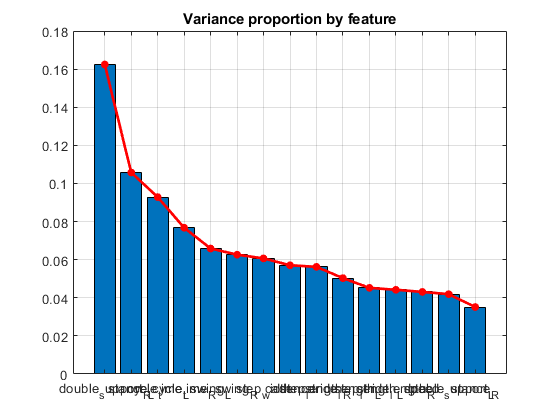

%measuring variance
V = var(myData{:,10:24});
spaciotemporalvars=myData.Properties.VariableNames(10:24);
[V,idx] = sort(V,'descend');
varianceTable = array2table(V,'VariableNames',spaciotemporalvars(idx),'RowNames',"Variance:")



%variance proportion

V = V/sum(V);
figure;
bar(V);
hold on; box on; grid on;
plot(V,'r.-','LineWidth',2,'MarkerSize',20);

grpSummary = 3×13 table
     note      GroupCount    mean_stance_division    sum_stance_division    min_stance_division    max_stance_division    range_stance_division    median_stance_division    mode_stance_division    var_stance_division    std_stance_division    nummissing_stance_division    nnz_stance_division
    _______    __________    ____________________    ___________________    ___________________    ___________________    _____________________    ______________________    ____________________    ___________________    ___________________    ________________________

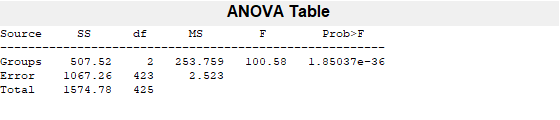

p = 1.8504e-36

hold off;
set(gca,'Xtick',1:length(spaciotemporalvars),'XTickLabel',spaciotemporalvars(idx));
title('Variance proportion by feature')



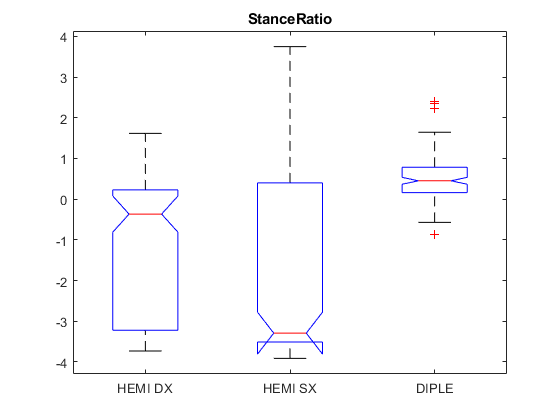

%correlation

variable = "stance_division";
grpSummary = groupsummary(myData,'note','all',variable)



%anova
p = anova1(myData.(variable),myData.note)
title('StanceRatio') %the anova1() creates a boxplot by default
%if pvalue is small, it means that the variables are related and can be used as a predictor for the other, Traditionally, p < 0.05 or 0.01  is considered sufficient evidence to conclude your features are dependent, p-value is a good estimator for the probability of independence
%a notched boxplot is also represented, The 'notches' on either side of the medians in the box plot represent the bounds of the 95% confidence interval


PCA

%preparing dataset for pca (continues features in a form of matrix)
myDataMatrix = myData{:,[10:24, 3349:end]};



%When performing PCA, the features should also have 0 mean and possess similar scales. The code below scales and mean-centers the features in each column of X, All features will then have a mean of 0 and values in the range [-0.5,0.5]
mu = mean(myDataMatrix);
r = range(myDataMatrix);
myDataMatrix = (myDataMatrix-mu)./r; 



%computing principal components, scores and variances
[P,S,V] = pca(myDataMatrix);
%The components are ordered by decreasing variance so that P(:,1) contains the first principle component ...
%S(:,1) contains the scores for the first principle component




%VERY IMPORTANT NOTES:
%remember you must also mean-center and scale new data. In particular, you should use the original data means and scales.
%remember (S=myDataMatrix*P), While this conversion is not usually necessary at first (since pca function provides scores as an output), you will have to convert any new data to scores before using it with a supervised or unsupervised learning model trained on the principle component features
%For example, the new data scores can be computed using this code: Xnew = (Xnew-mu)./r; Snew = Xnew*P(:,1:components);

Some Visualizations for the PCA

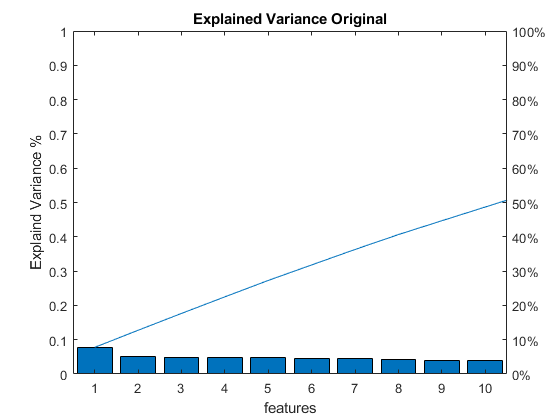

%plotting the variance explained by original features

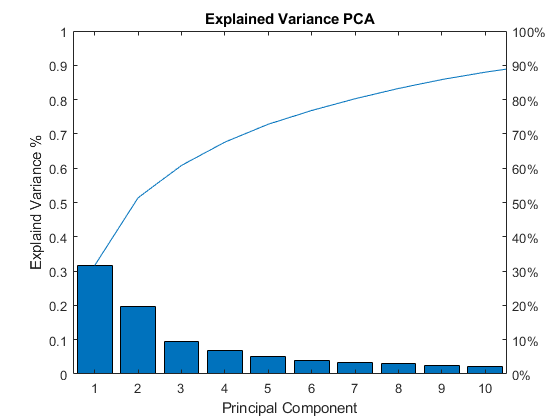

%Clearly, variance is distributed much more evenly among the original features
VOrig = var(myDataMatrix);
VOrig = sort(VOrig,'descend');
VOrig = VOrig/sum(VOrig); % Normalize the variance so the total is 1
pareto(VOrig)
title('Explained Variance Original')
ylabel('Explaind Variance %')

xlabel('features')

%plotting the variance explained by each component

ans = 1×31 cell array
    {'speed'}    {'cadence'}    {'cycle_time_R'}    {'cycle_time_L'}    {'stance_R'}    {'stance_L'}    {'swing_R'}    {'swing_L'}    {'double_support_R'}    {'double_support_L'}    {'stride_length_R'}    {'stride_length_L'}    {'step_length_R'}    {'step_length_L'}    {'step_width'}    {'cycle_time_division'}    {'stance_division'}    {'swing_division'}    {'double_support_division'}    {'stride_length_division'}    {'step_length_division'}    {'PROTA_R_median'}    {'PROTA_L_median'}    {'HPFE_R_median'}    {'HPFE_L_median'}    {'KFE_R_median'}    {'KFE_L_median'}    {'HPP_R_min'}    {'HPP_L_min'}    {'AP_R_max'}    {'AP_L_max'}


V = V/sum(V); % Normalize the variance so the total is 1

a = 1×31 cell array
    {'Speed'}    {'Cadence'}    {'CycleTime_R'}    {'CycleTime_L'}    {'Stance_R'}    {'Stance_L'}    {'Swing_R'}    {'Swing_L'}    {'DoubleSupport_R'}    {'DoubleSupport_L'}    {'StrideLength_R'}    {'StrideLength_L'}    {'StepLength_R'}    {'StepLength_L'}    {'StepWidth'}    {'CycleTimeDivision'}    {'StanceDivision'}    {'SwingDivision'}    {'DoubleSupportDivision'}    {'StrideLengthDivision'}    {'StepLengthDivision'}    {'PROTAMedian_R'}    {'PROTAMedian_L'}    {'HPFEMedian_R'}    {'HPFEMedian_L'}    {'KFEMedian_R'}    {'KFEMedian_L'}    {'HPPMedian_R'}    {'HPPMin_L'}    {'APMax_R'}    {'APMax_L'}


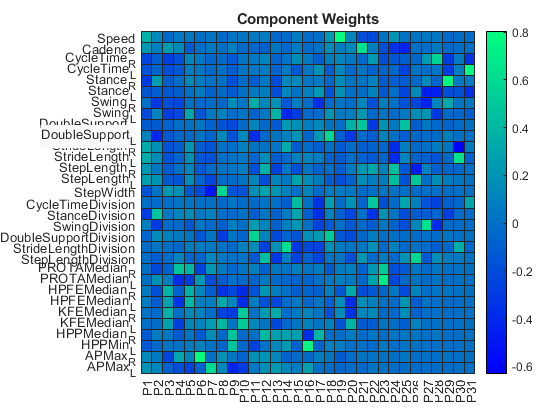

pareto(V)
title('Explained Variance PCA')
ylabel('Explaind Variance %')

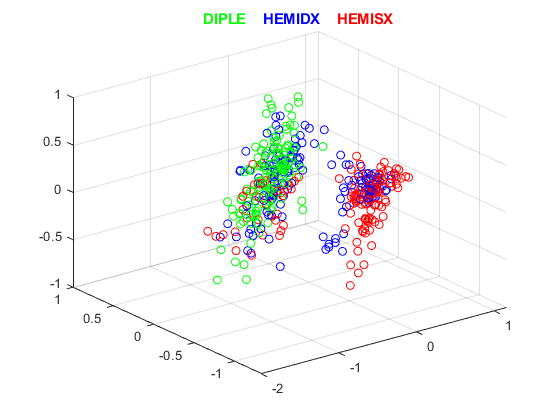

xlabel('Principal Component')

%Relating the principle components to the original variables
myData.Properties.VariableNames([10:24, 3349:end])
a={'Speed'    'Cadence'    'CycleTime_R'    'CycleTime_L'    'Stance_R'    'Stance_L'    'Swing_R'    'Swing_L'    'DoubleSupport_R'    'DoubleSupport_L' 'StrideLength_R'    'StrideLength_L'    'StepLength_R'    'StepLength_L'    'StepWidth'    'CycleTimeDivision'    'StanceDivision'    'SwingDivision' 'DoubleSupportDivision'    'StrideLengthDivision'    'StepLengthDivision'    'PROTAMedian_R'    'PROTAMedian_L'    'HPFEMedian_R'    'HPFEMedian_L' 'KFEMedian_R'    'KFEMedian_L'    'HPPMedian_R'    'HPPMin_L'    'APMax_R'    'APMax_L'}


heatmap(P,'XDisplayLabels',"P"+(1:31),'YDisplayLabels',a,'Title','Component Weights','Colormap',winter);

%scatter plot of the first 3 components as they explain most of variance,it will give us an insight
SandNote= array2table(S);

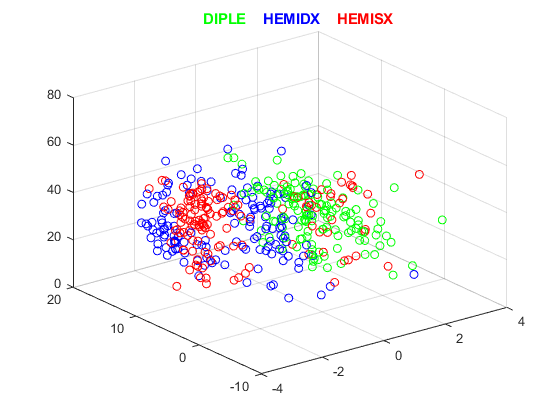

SandNote.note = myData.note;
scatter3(SandNote{SandNote.note == 'DIPLE',1},SandNote{SandNote.note == 'DIPLE',2},SandNote{SandNote.note == 'DIPLE',3},'g')
hold on
scatter3(SandNote{SandNote.note == 'HEMI DX',1},SandNote{SandNote.note == 'HEMI DX',2},SandNote{SandNote.note == 'HEMI DX',3},'b')
scatter3(SandNote{SandNote.note == 'HEMI SX',1},SandNote{SandNote.note == 'HEMI SX',2},SandNote{SandNote.note == 'HEMI SX',3},'r')
hold off

title('   \color{green} DIPLE   \color{blue} HEMIDX   \color{red} HEMISX')

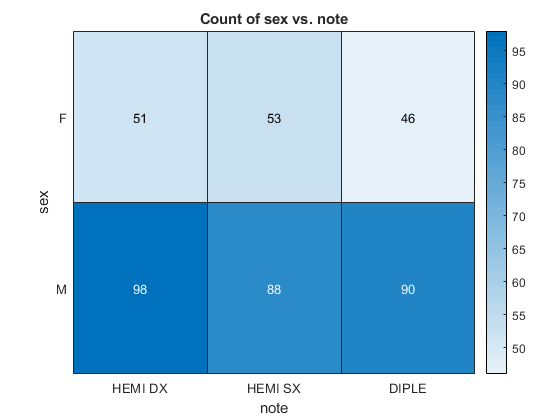

ans =   HeatmapChart (Count of sex vs. note) with properties:

      SourceTable: [426×3364 table]
        XVariable: 'note'
        YVariable: 'sex'
    ColorVariable: ''
      ColorMethod: 'count'

  Show all properties


%an example visualization using only 3 attributes
scatter3(myData{myData.note == 'DIPLE','stance_division'},myData{myData.note == 'DIPLE','APF_R41'},myData{myData.note == 'DIPLE','HPFE_R11'},'g')

hold on
scatter3(myData{myData.note == 'HEMI DX','stance_division'},myData{myData.note == 'HEMI DX','APF_R41'},myData{myData.note == 'HEMI DX','HPFE_R11'},'b')
scatter3(myData{myData.note == 'HEMI SX','stance_division'},myData{myData.note == 'HEMI SX','APF_R41'},myData{myData.note == 'HEMI SX','HPFE_R11'},'r')
hold off

title('   \color{green} DIPLE   \color{blue} HEMIDX   \color{red} HEMISX')

heatmap(filledData_234,'note',"sex")